# ***Forward_Modeling.mlx***

Το script αυτό πραγματοποιεί τη διαδικασία του Forward Modeling ενός ρήγματος Uniform Slip σε επιλεγμένα σημεία-σταθμούς στην επιφάνεια του εδάφους. Στη συνέχεια προσθέτει θόρυβο είτε στις τιμές ολισθήσεων που υπολογίζονται (συνθετικές μετρήσεις) είτε στις αρχικές παραμέτρους του ρήγματος, δημιουργώντας νέα σύνολα μετακινήσεων.

Αρχικά θέτουμε ως θέση που τρέχει η Matlab το εσωτερικό του φακέλου 'Project'. Όπου υπάρχει σε σχόλιο το "-->", η μεταβλητή πρέπει να εισαχθεί από το χρήστη ανάλογα με τα δεδομένα του προβλήματος. 

# Forward Modeling

% Copyright (c) 2018, Livadas – Stathakopoulos Ioannis (yiannislibad@hotmail.gr)
% Covered by MIT Licence
% Πραγματοποιείται εντός αναφορά σχετικά με χρήση scripts ή λογισμικού τρίτων.

% Επιτρέπουμε στη Matlab να έχει πρόσβαση στα περιεχόμενα του φακέλου Project.
folder = fileparts(which('Forward_Modeling.mlx'));
addpath(genpath(folder));
clearvars

## Εισαγωγή Δεδομένων

Αρχικά δίνουμε τις τιμές των χαρακτηριστικών του ρήγματος.

Depth = 0.5;            % --> Top Depth, σε km
Strike = 315;           % --> Strike, σε μοίρες
Dip = 45;               % --> Dip, σε μοίρες
Leng = 12;              % --> Lenth, σε km
Wid = 7;                % --> Width, σε km
Rake = 270;             % --> Rake, σε μοίρες
Slip = 0.00075;         % --> Slip, σε km

% Αφού το Slip δίνεται σε km και τα υπόλοιπα μήκη σε km, το Factor = 1/1 = 1

Depth_c = Depth + sin(Dip*pi/180)*Wid/2; ...
    % Η okada85 ζητά το Depth του fault centroid

Slip_Scale = 0.5 * 10^6; % --> Η κλίμακα των slip για την καλύτερη αναπαράσταση τους
    % Εδώ π.χ. 1 km στο γράφημα θα αντιστοιχεί σε 10^3/Slip_Scale (m) = 5mm
    
Slip_Scale_z = 4 * Slip_Scale;    % -->  Η κλίμακα των uZ slip 

Δίνουμε και τις συντεταγμένες του κέντρου του ρήγματος σε μορφή [degrees minutes seconds]. Υπολογίζονται τα northing και easting του κέντρου σε km, με χρήση του script 'll2utm.m' του François Beauducel. Κάθε φορά που ακολουθείται η ίδια ή η αντίστροφη μετατροπή (latitude-longitude <-> UTM), χρησιμοποιούνται τα script 'll2utm.m' και 'utm2ll.m' του François Beauducel.

latitude_c = [39 34 22];      % --> Latitude, N του fault centroid
longitude_c = [22 34 40];     % --> Longitude, E του fault centroid

lat_c = dms2degrees(latitude_c);
long_c = dms2degrees(longitude_c);

[E_c,N_c] = ll2utm(lat_c,long_c);
N_c = N_c/1000; E_c = E_c/1000;   % Συντεταγμένες UTM του fault centroid σε km


## Ίχνος Ρήγματος (Fault Trace)

Υπολογίζεται και το ίχνος του ρήγματος (προέκταση του στην επιφάνεια του εδάφους).

trace_A_N = sin(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    - cos(Strike*pi/180)*Leng/2;
trace_B_N = sin(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    + cos(Strike*pi/180)*Leng/2;

trace_A_E = -cos(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    - sin(Strike*pi/180)*Leng/2;
trace_B_E = -cos(Strike*pi/180)*(Wid/2 + Depth/tan(Dip*pi/180))...
    + sin(Strike*pi/180)*Leng/2;

N_trace = linspace(trace_A_N,trace_B_N,100);   % Το Northing του ίχνους
E_trace = linspace(trace_A_E,trace_B_E,100);   % Το Easting του ίχνους
Z_trace = zeros(100);

Βρίσκονται οι συντεταγμένες των δύο σημείων που ορίζουν το ευθύγραμμο τμήμα του ίχνους. 

**!!! Προσοχή! Εάν το ρήγμα βρίσκεται στο νότιο ημισφαίριο, η τιμή του zone (utm) θέλει αρνητική τιμή (-) κατά τη χρήση στο script 'utm2ll.m' !!!**

zone = utmzone(lat_c,long_c);
zone(end) = [];
zone_num = str2double(zone);

[lat_A,long_A] = utm2ll((E_c+trace_A_E)*1000,(N_c+trace_A_N)*1000,...
    zone_num);

[lat_B,long_B] = utm2ll((E_c+trace_B_E)*1000,(N_c+trace_B_N)*1000,...
    zone_num);

table_AB = [trace_A_E trace_A_N trace_A_E+E_c trace_A_N+N_c long_A lat_A; ...
    trace_B_E trace_B_N trace_B_E+E_c trace_B_N+N_c long_B lat_B]; ...
    % Πίνακας για χρήση στο excel

## Συνθετικά Δεδομένα

Στη συνέχεια ορίζουμε τον αριθμό σημείων στην επιφάνεια του εδάφους, για τα οποία θέλουμε να υπολογίσουμε τις μετακινήσεις τους από τα χαρακτηριστικά του ρήγματος.

points = 15;    % --> Αριθμός σημείων
points_names = num2str((1:points)');  % Όνομα σταθμών για απεικόνιση

Δίνονται οι πίνακες Ε, Ν, που εκφράζουν την απόσταση σε km καθενός σημείου από τα παραπάνω από το κέντρο του ρήγματος αναφοράς (fault centroid). Κάθε τιμή του πίνακα αποτελεί την τιμή του αντίστοιχου σημείου. Υπολογίζονται και οι συντεταγμένες τους σε μοίρες (latitude, longitude).

E = [-13; -26; -20; -5; -4; -15; 12; 10; 8; 25; 9; -10; 6; -8; 5]; % -->
N = [15; 10; -22; 15; -20; 0; 0; 8; 23; 15; -15; -15; -23; -5; 10];  % -->
Z = zeros(points,1);

[lat_points,long_points] = utm2ll((E_c+E)*1000,(N_c+N)*1000,...
    zone_num);
coordinates_points = [lat_points long_points];

table_points = [E N E+E_c N+N_c long_points lat_points]; ...
    % Πίνακας για χρήση στο excel

Υπολογίζονται τα uE, uN και uZ των παραπάνω σημείων, που εκφράζουν τις μετακινήσεις τους, με τη διαδικασία του Forward Modeling. Σχεδιάζονται ρήγμα και ολισθήσεις των σημείων στο επίπεδο East, North.

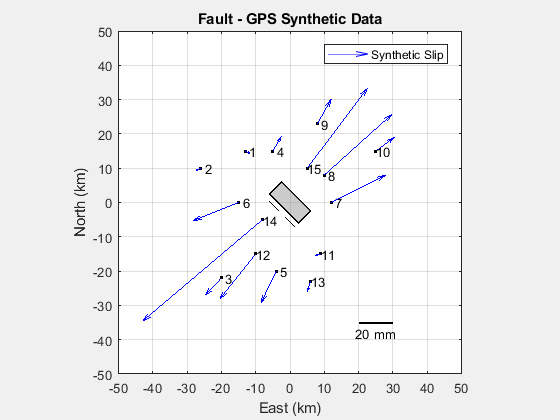

figure()

% Forward Modeling και απεικόνιση του ρήγματος
[uE,uN,uZ] = okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0,'plot'); 
hold on

% Απεικόνιση των σημείων - σταθμών
plot3(E,N,Z,'.k')    
text(E,N,Z,points_names);

% Απεικόνιση των ολισθήσεων στους σταθμούς με μορφή vectors
p1 = quiver3(E,N,Z,uE*Slip_Scale,uN*Slip_Scale,uZ*Slip_Scale,'b',...
    'AutoScale','off','MaxHeadSize',0.1);

% Υπόμνημα
leg = legend(p1,'Synthetic Slip');
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Τα ticks των αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Δημιουργία μπάρας κλίμακας για το μέγεθος των ολισθήσεων
obj = scalebar_ed1;
obj.XLen = 10; obj.YLen = 0;
obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
obj.hTextX_Pos = [-1,-3];
obj.Position = [20,-35];

% Labels, εύρος αξόνων, γωνία προβολής και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-50 50 -50 50 -20 20])  % --> Μεταβάλλω ανάλογα
view([0 90]);                   % Για προβολή από πάνω
title('Fault - GPS Synthetic Data')

Σχεδιάζονται οι κατακόρυφες ολισθήσεις uZ των σταθμών.

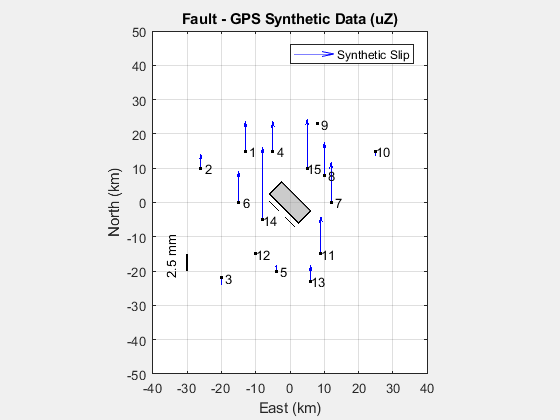

figure()

% Forward Modeling και απεικόνιση του ρήγματος
okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0); 
hold on

% Απεικόνιση των σημείων - σταθμών
plot3(E,N,Z,'.k')    

text(E,N,Z,points_names);

% Απεικόνιση των ολισθήσεων στους σταθμούς με μορφή vectors
p1 = quiver3(E,N,Z,zeros(points,1),uZ*Slip_Scale_z,zeros(points,1),'b',...
    'AutoScale','off','MaxHeadSize',0.1);

% Υπόμνημα
leg = legend(p1,'Synthetic Slip');
leg.AutoUpdate = 'off';
leg.Location = 'northeast';

% Σχεδίαση του ίχνους
plot3(E_trace,N_trace,Z_trace,'k--')

% Τα ticks των αξόνων
xticks(-500:10:500)
yticks(-500:10:500)
zticks(-500:10:500)

% Δημιουργία μπάρας κλίμακας για το μέγεθος των ολισθήσεων
obj = scalebar_ed1;
obj.XLen = 0; obj.YLen = 5;
obj.YUnit = [num2str(1/Slip_Scale_z*10^6*obj.YLen) ' mm'];
obj.hTextY_Pos = [-5,-2];
obj.Position = [-30 -20];

% Labels, εύρος αξόνων, γωνία προβολής και τίτλος
xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
axis([-40 40 -50 50 -40 40])  % --> Μεταβάλλω ανάλογα
view([0 90]);                   % Για προβολή από πάνω
title('Fault - GPS Synthetic Data (uZ)')

Σχεδιάζονται οι κατακόρυφες ολισθήσεις uZ των σταθμών (διάγραμμα stems).

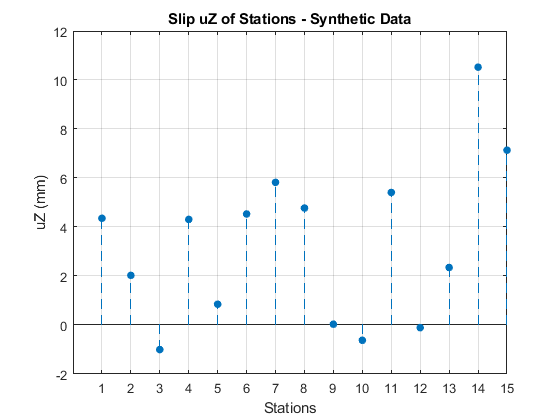

% Σχεδίαση κατακόρυφων μετακινήσεων σε διάγραμμα stems
figure()
stem(1:points,uZ*10^6,'filled','MarkerSize',5,'LineStyle','--')

grid on
xticks(1:points);
xlabel('Stations'); ylabel('uZ (mm)')
title('Slip uZ of Stations - Synthetic Data');


table_slips = [uE uN uZ]*10^5;   % Τα slips των σταθμών για Excel

Αυτές είναι οι αναμενόμενες μετακινήσεις (συνθετικά δεδομένα GPS).

# Προσθήκη θορύβου

## Θόρυβος στα συνθετικά δεδομένα (σh - 3mm, σv - 5mm)

Στη συνέχεια θα προσθέσουμε θόρυβο στα συνθετικά δεδομένα. Αρχικά θα δοκιμάσουμε με μικρό θόρυβο (3mm στις οριζόντιες μετακινήσεις και 5mm στις κατακόρυφες), και θα δημιουργήσουμε 10 νέα σύνολα μετατοπίσεων.

n_models1 = 10;      % --> Ο αριθμός των νέων μοντέλων που θα δημιουργηθούν
sigma_uE1 = 3*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση E σε km
sigma_uN1 = 3*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση N σε km
sigma_uZ1 = 5*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση Z σε km

sigma_uE1_t = repmat(sigma_uE1,1,n_models1);
sigma_uN1_t = repmat(sigma_uN1,1,n_models1);
sigma_uZ1_t = repmat(sigma_uZ1,1,n_models1);

**!!! Εάν τρέξουμε το βήμα αυτό δημιουργούνται νέα μοντέλα, καθώς δημιουργείται τυχαίος θόρυβος βάσει του σφάλματος !!!**

% Δημιουργία νέων τιμών ολισθήσεων με τυχαίο θόρυβο
uE_noise1 = sigma_uE1_t .* randn(points,n_models1);
uN_noise1 = sigma_uN1_t .* randn(points,n_models1);
uZ_noise1 = sigma_uZ1_t .* randn(points,n_models1);

uE_New1 = uE_noise1 + repmat(uE,1,n_models1);
uN_New1 = uN_noise1 + repmat(uN,1,n_models1);
uZ_New1 = uZ_noise1 + repmat(uZ,1,n_models1);

% Υπολογισμός SNR
SNR_uE1 = zeros (1,n_models1);
SNR_uN1 = zeros (1,n_models1);
SNR_uZ1 = zeros (1,n_models1);


for count = 1:n_models1
    
    start = (count-1)*3 + 1;
    
    % Πίνακας slips για χρήση στο Excel
    table_slips_New1(:,start:start+2) = [uE_New1(:,count) ...
        uN_New1(:,count) uZ_New1(:,count)]*10^5;

    SNR_uE1(count) = snr(uE,uE_noise1(:,count));
    SNR_uN1(count) = snr(uN,uN_noise1(:,count));
    SNR_uZ1(count) = snr(uZ,uZ_noise1(:,count));
        
end

Απεικονίζονται ενδεικτικά κάποια από αυτά σε σύγκριση με το αρχικό μοντέλο, στο επίπεδο East, North.

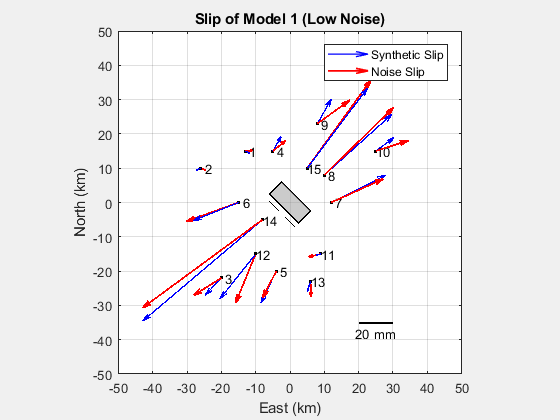

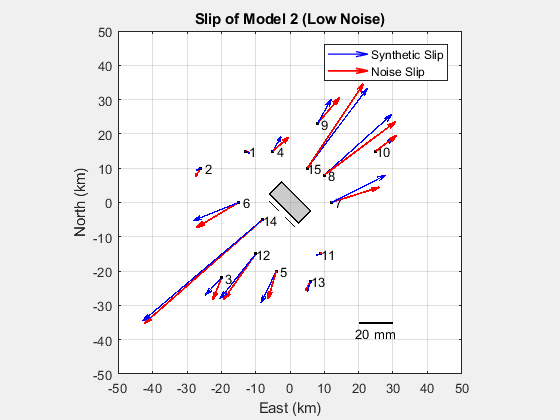

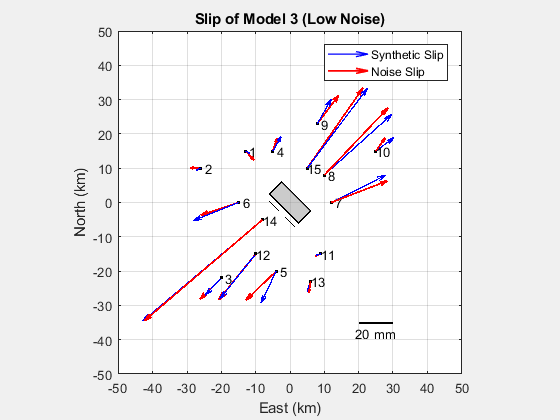

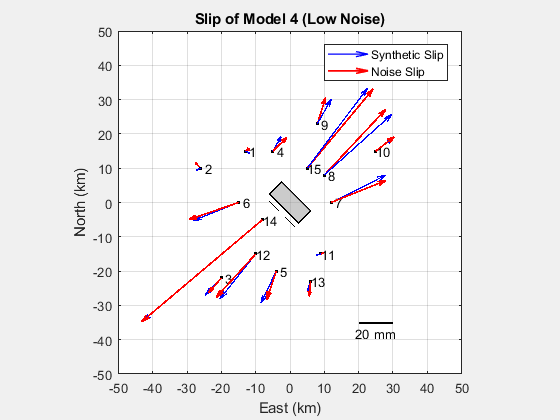

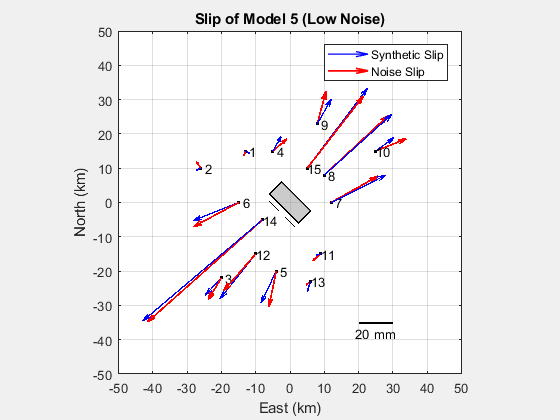

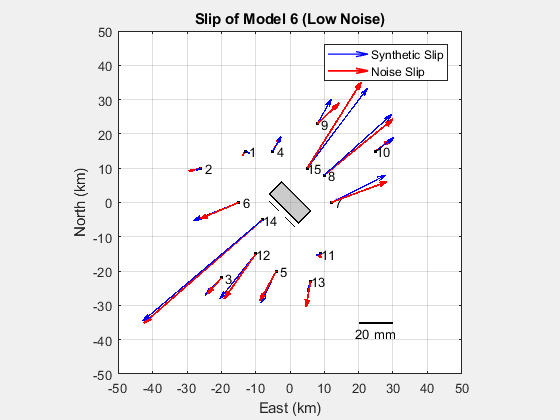

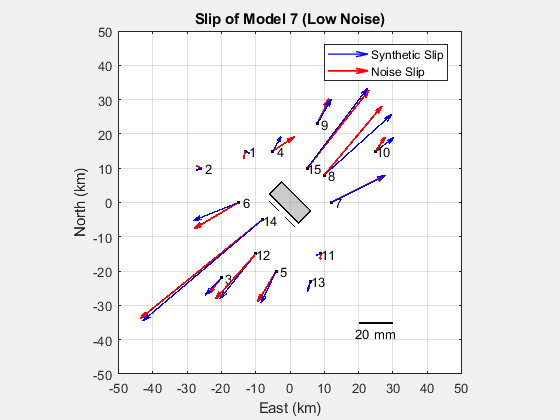

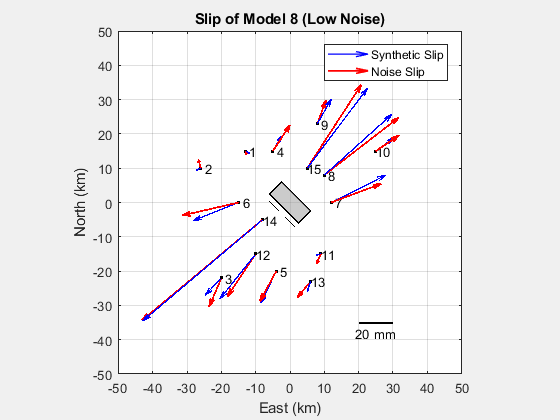

f_models1 = 10;  % --> Δώσε πόσα μοντέλα θέλεις να απεικονιστούν

for count = 1:f_models1
    figure()

    % Απεικόνιση του ρήγματος
    okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
    hold on

    % Απεικόνιση των σημείων - σταθμών
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);

    % Απεικόνιση των μετρημένων slips των σταθμών
    p1 = quiver3(E,N,Z,uE*Slip_Scale,uN*Slip_Scale,uZ*Slip_Scale,...
        'b','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);
    
    % Απεικόνιση του συνόλου slips των σταθμών μετά την προσθήκη θορύβου
    p2 = quiver3(E,N,Z,uE_New1(:,count)*Slip_Scale,...
        uN_New1(:,count)*Slip_Scale,uZ_New1(:,count)*Slip_Scale,...
        'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);

    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    % Σχεδιασμός ίχνους
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Ticks αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)

    % Κλίμακα μεγέθους των slips
    obj = scalebar_ed1;
    obj.XLen = 10; obj.YLen = 0;
    obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
    obj.hTextX_Pos = [-1,-3];
    obj.Position = [20,-35];
    
    % Labels, τίτλος, εύρος αξόνων και γωνία προβολής
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    title(['Slip of Model ' num2str(count) ' (Low Noise)'])
    axis([-50 50 -50 50])   % --> Μεταβάλλω ανάλογα
    view([0 90]);             % Για προβολή από πάνω

end

Και για τις κατακόρυφες ολισθήσεις:

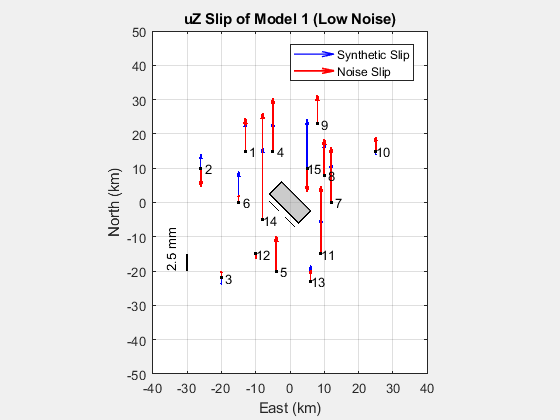

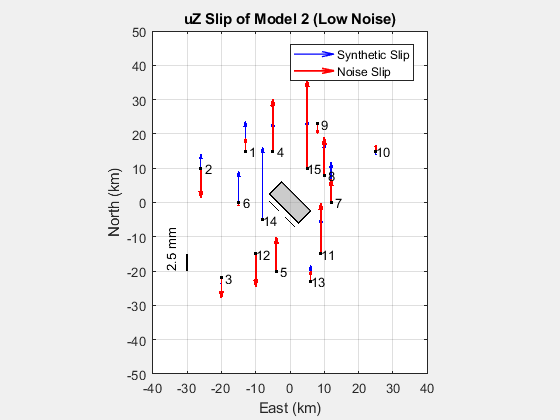

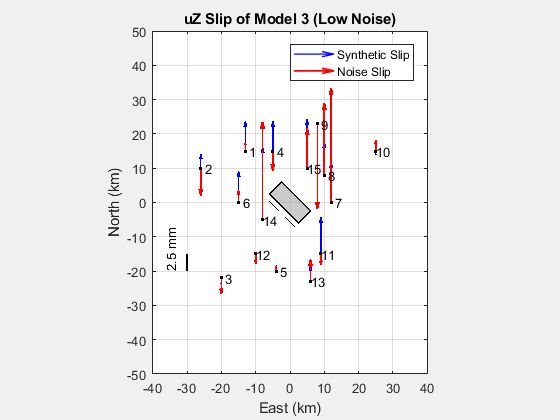

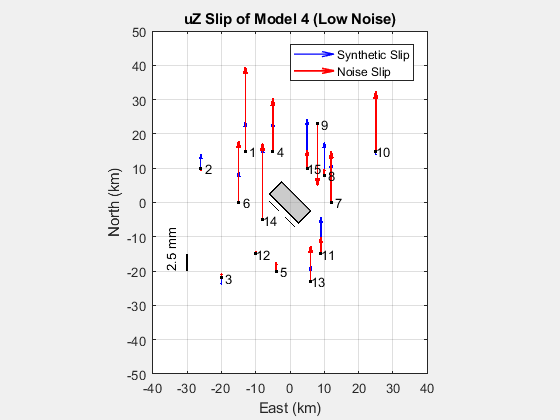

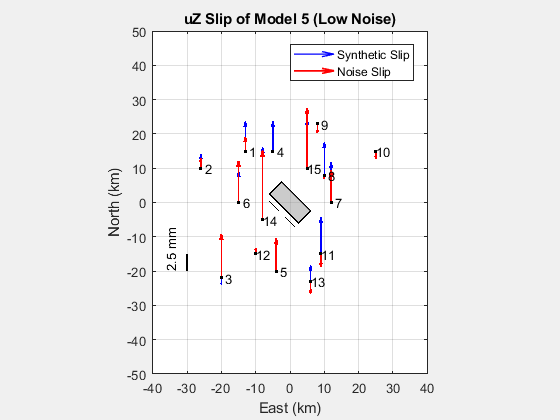

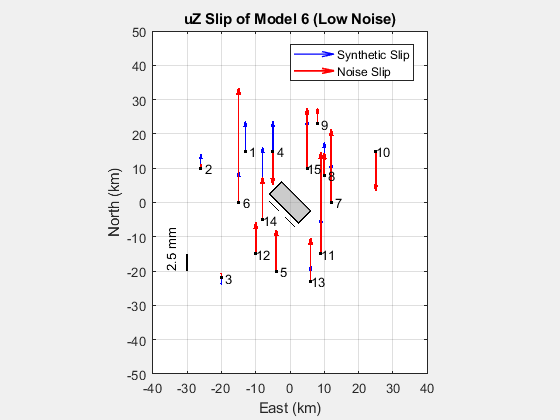

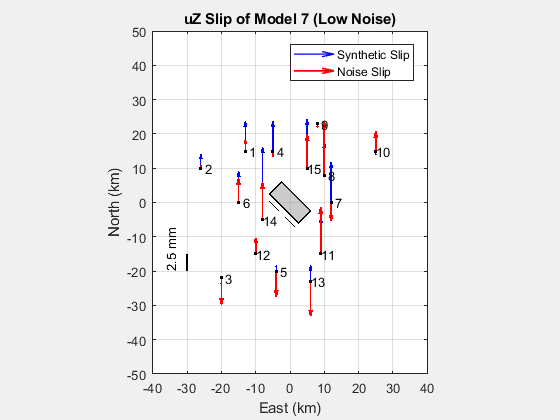

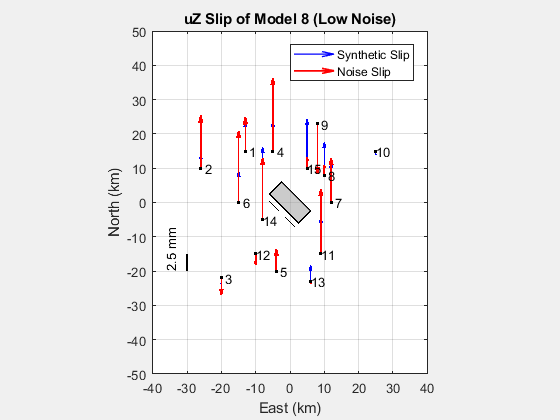

for count = 1:f_models1
    figure()

    % Απεικόνιση του ρήγματος
    okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
    hold on

    % Απεικόνιση των σημείων - σταθμών
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);

    % Απεικόνιση των μετρημένων slips των σταθμών
    p1 = quiver3(E,N,Z,zeros(points,1),uZ*Slip_Scale_z,zeros(points,1),...
        'b','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);
    
    % Απεικόνιση του συνόλου slips των σταθμών μετά την προσθήκη θορύβου
    p2 = quiver3(E,N,Z,zeros(points,1),...
        uZ_New1(:,count)*Slip_Scale_z,zeros(points,1),...
        'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);

    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    % Σχεδιασμός ίχνους
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Ticks αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)

    % Κλίμακα μεγέθους των slips
    obj = scalebar_ed1;
    obj.XLen = 0; obj.YLen = 5;
    obj.YUnit = [num2str(1/Slip_Scale_z*10^6*obj.YLen) ' mm'];
    obj.hTextY_Pos = [-5,0];
    obj.Position = [-30,-20];
    
    % Labels, τίτλος, εύρος αξόνων και γωνία προβολής
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    title(['uZ Slip of Model ' num2str(count) ' (Low Noise)'])
    axis([-40 40 -50 50])   % --> Μεταβάλλω ανάλογα
    view([0 90]);             % Για προβολή από πάνω

end

Και σε κατακόρυφη προβολή με το σφάλμα μετρήσεων:

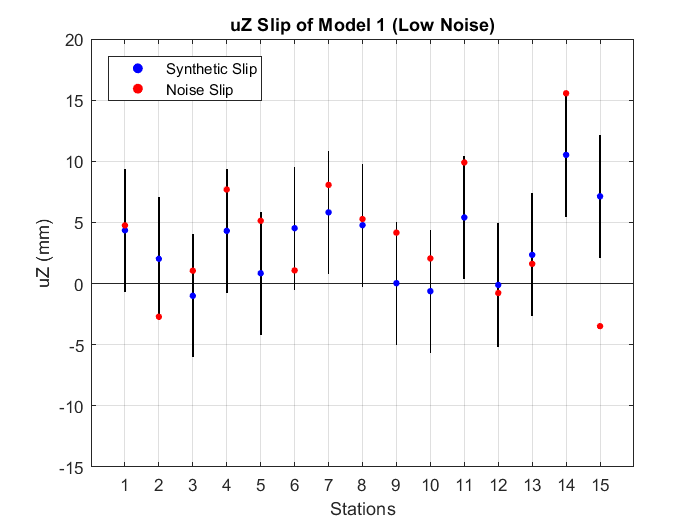

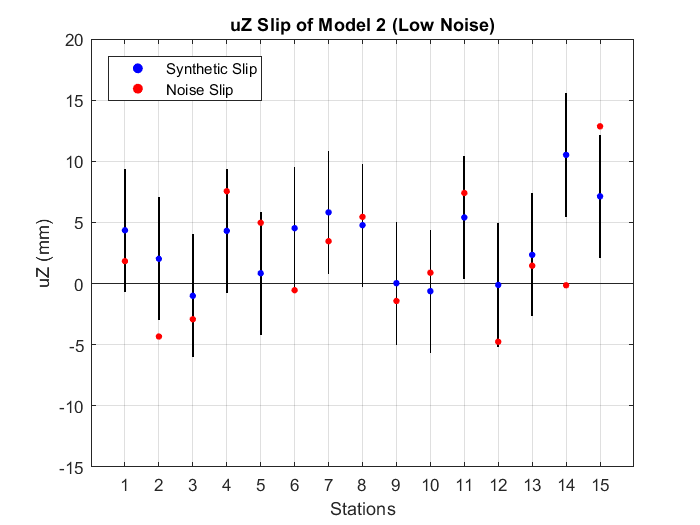

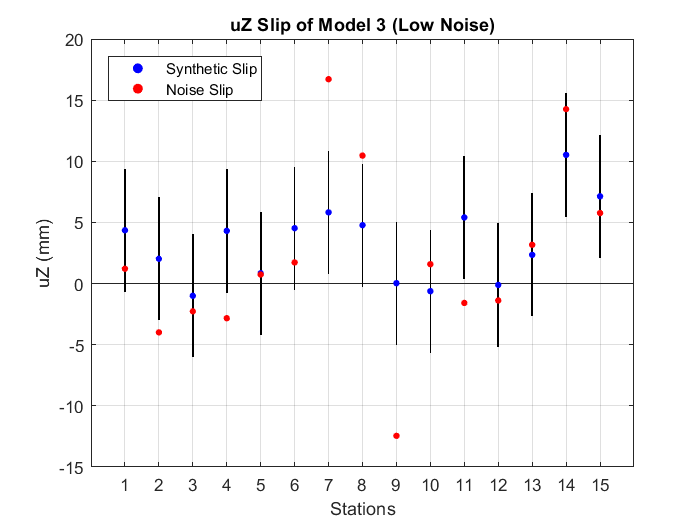

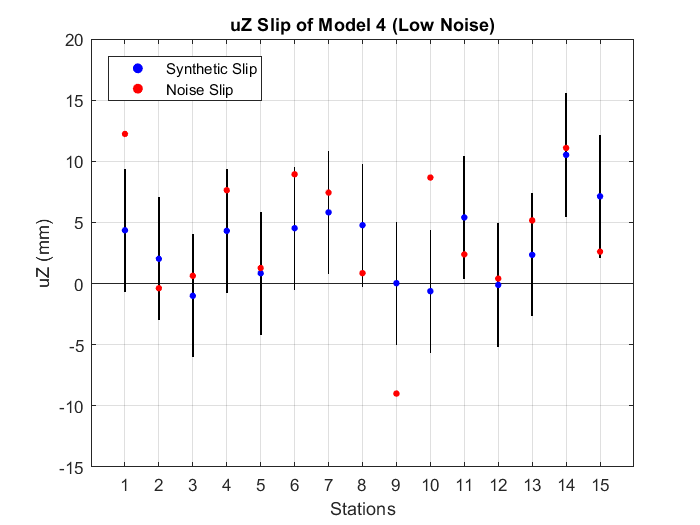

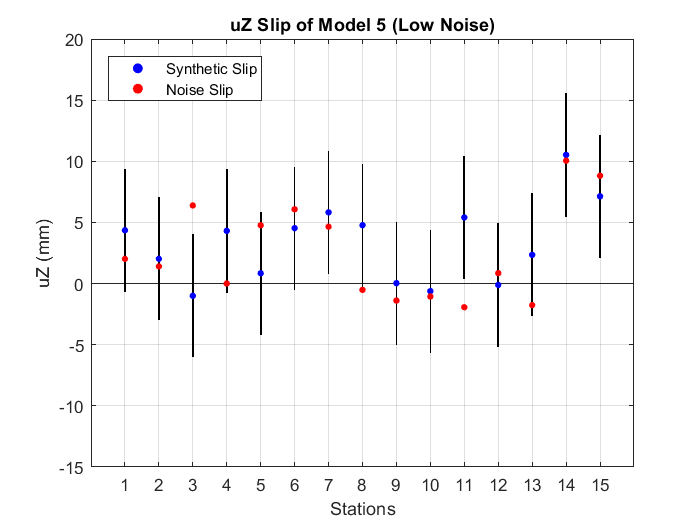

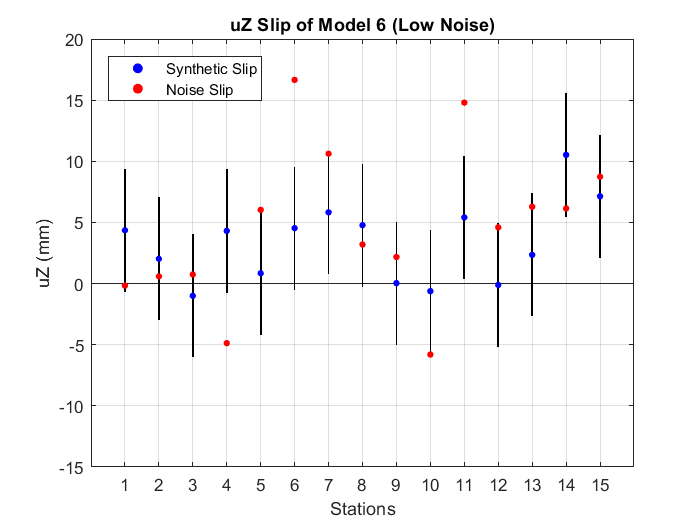

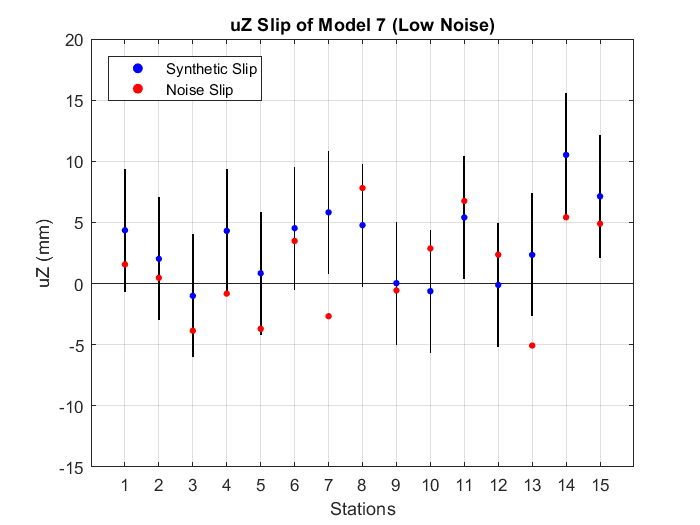

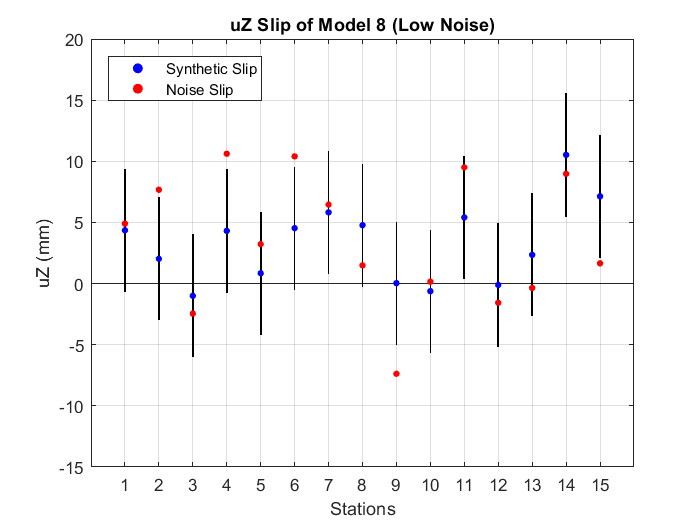

for count = 1:f_models1
    
    figure()
    
    % Απεικόνιση της γραμμής σφάλματος σ. Η γραμμή εκφράζει το εύρος [-σ,σ]
    vert_slip1 = [uZ - sigma_uZ1, repmat(2*sigma_uZ1,points,1)]*10^6;
    h = bar(vert_slip1,0.02,'stacked');
    set(h(1), 'Visible','off')
    hold on
    
    %Απεικόνιση των μετρημένων τιμών slip
    p1 = scatter(1:points,uZ*10^6,15,'filled','b');
    
    %Απεικόνιση των τιμών slip με θόρυβο
    p2 = scatter(1:points,uZ_New1(:,count)*10^6,15,'filled','r');
    grid on
    
    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northwest';
    
    % Ticks αξόνων, Labels, τίτλος
    xticks(1:points)
    yticks(-500:5:500)
    axis([0 points+1 -15 20]) % --> Μεταβάλλω ανάλογα ή αφαιρώ
    xlabel('Stations'); ylabel('uZ (mm)')
    title(['uZ Slip of Model ' num2str(count) ' (Low Noise)']);
end

## Θόρυβος στα συνθετικά δεδομένα (σh - 10mm, σv - 15mm)

Συνεχίζουμε με μεγάλο θόρυβο στα συνθετικά δεδομένα (οριζόντιες μετακινήσεις 10mm, κατακόρυφες 15mm), και δημιουργούμε 10 νέα σύνολα μετατοπίσεων.

n_models2 = 10;   % --> Ο αριθμός των νέων μοντέλων που θα δημιουργηθούν
sigma_uE2 = 10*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση E σε km
sigma_uN2 = 10*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση N σε km
sigma_uZ2 = 15*10^-6; % --> Το σφάλμα μέτρησης στη διεύθυνση Z σε km

sigma_uE2_t = repmat(sigma_uE2,1,n_models2);
sigma_uN2_t = repmat(sigma_uN2,1,n_models2);
sigma_uZ2_t = repmat(sigma_uZ2,1,n_models2);

**!!! Εάν τρέξουμε το βήμα αυτό δημιουργούνται νέα μοντέλα, καθώς δημιουργείται τυχαίος θόρυβος βάσει του σφάλματος !!!**

uE_noise2 = sigma_uE2_t .* randn(points,n_models2);
uN_noise2 = sigma_uN2_t .* randn(points,n_models2);
uZ_noise2 = sigma_uZ2_t .* randn(points,n_models2);

uE_New2 = uE_noise2 + repmat(uE,1,n_models2);
uN_New2 = uN_noise2 + repmat(uN,1,n_models2);
uZ_New2 = uZ_noise2 + repmat(uZ,1,n_models2);

% Υπολογισμός SNR
SNR_uE2 = zeros(1,n_models2);
SNR_uN2 = zeros(1,n_models2);
SNR_uZ2 = zeros(1,n_models2);

for count = 1:n_models2
    
    start = (count-1)*3 + 1;
    
    % Πίνακας slips για χρήση στο Excel (cm)
    table_slips_New2(:,start:start+2) = [uE_New2(:,count) ...
        uN_New2(:,count) uZ_New2(:,count)]*10^5;

    SNR_uE2(count) = snr(uE,uE_noise2(:,count));
    SNR_uN2(count) = snr(uN,uN_noise2(:,count));
    SNR_uZ2(count) = snr(uZ,uZ_noise2(:,count));
        
end

Απεικονίζονται ενδεικτικά κάποια από αυτά σε σύγκριση με το αρχικό μοντέλο, στο επίπεδο East, North.

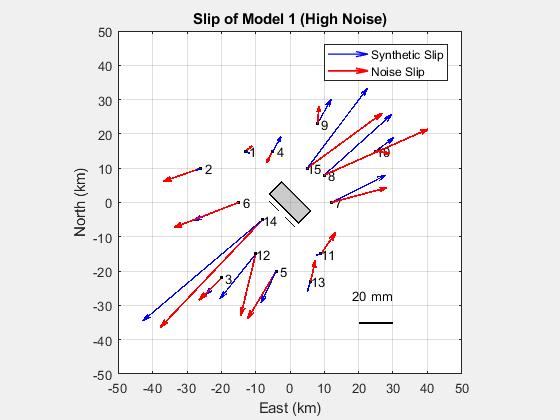

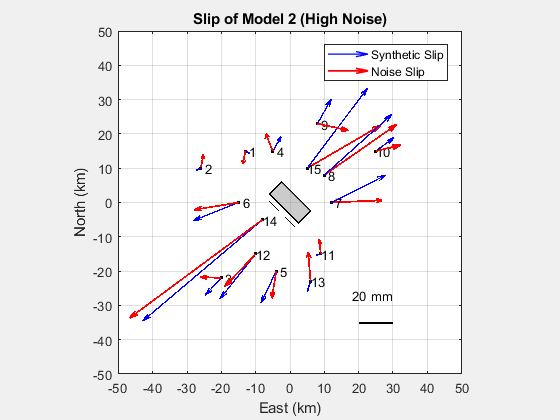

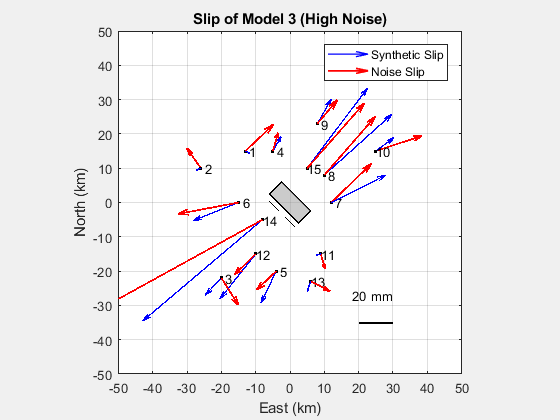

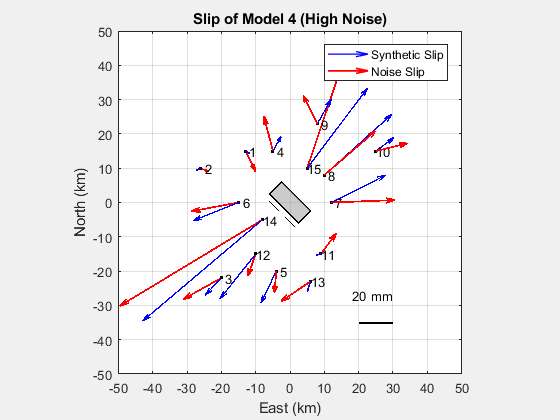

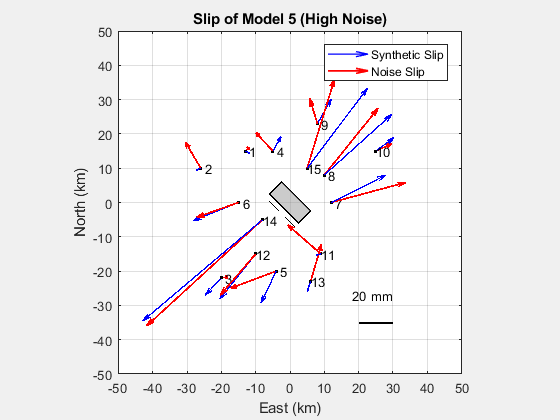

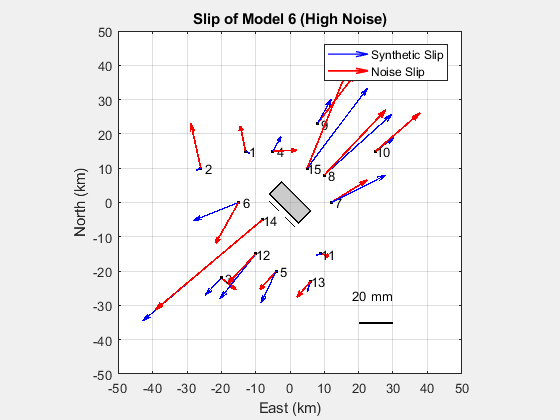

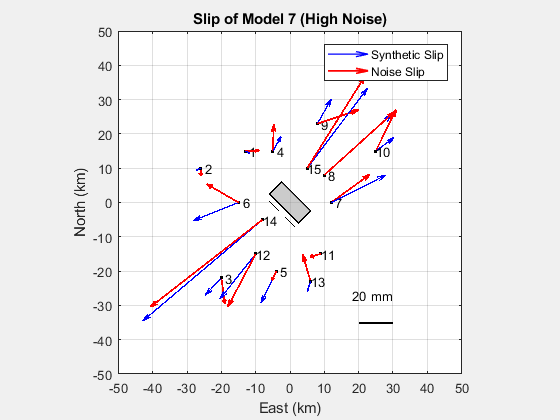

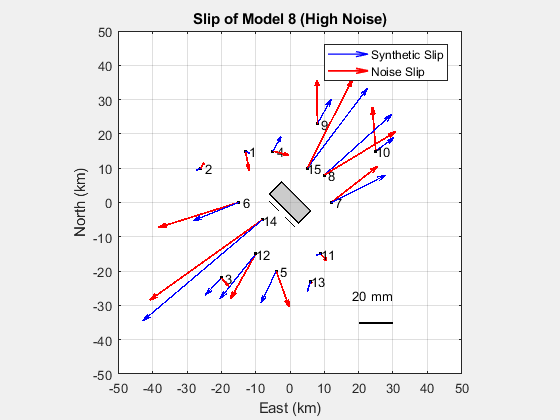

f_models2 = 10;  % --> Δώσε πόσα μοντέλα θέλεις να απεικονιστούν

for count = 1:f_models2
    figure()

    % Απεικόνιση ρήγματος
    okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
    hold on

    % Απεικόνιση σημείων - σταθμών
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);

    % Απεικόνιση μετρημένων τιμών ολίσθησης
    p1 = quiver3(E,N,Z,uE*Slip_Scale,uN*Slip_Scale,...
        uZ*Slip_Scale,'b','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

    % Απεικόνιση τιμών ολίσθησης με θόρυβο
    p2 = quiver3(E,N,Z,uE_New2(:,count)*Slip_Scale,...
        uN_New2(:,count)*Slip_Scale,uZ_New2(:,count)*Slip_Scale,...
        'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);
    
    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    % Σχεδίαση ίχνους
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Ticks αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)
    
    % Κλίμακα για μέγεθος των slips
    obj = scalebar_ed1;
    obj.XLen = 10; obj.YLen = 0;
    obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
    obj.hTextX_Pos = [-2,8];
    obj.Position = [20,-35];

    % Labels, τίτλος, εύρος αξόνων, γωνία προβολής
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    title(['Slip of Model ' num2str(count) ' (High Noise)'])
    axis([-50 50 -50 50])  % --> Μεταβάλλω ανάλογα
    view([0 90]);            % Για προβολή από πάνω
end

Και για τις κατακόρυφες ολισθήσεις:

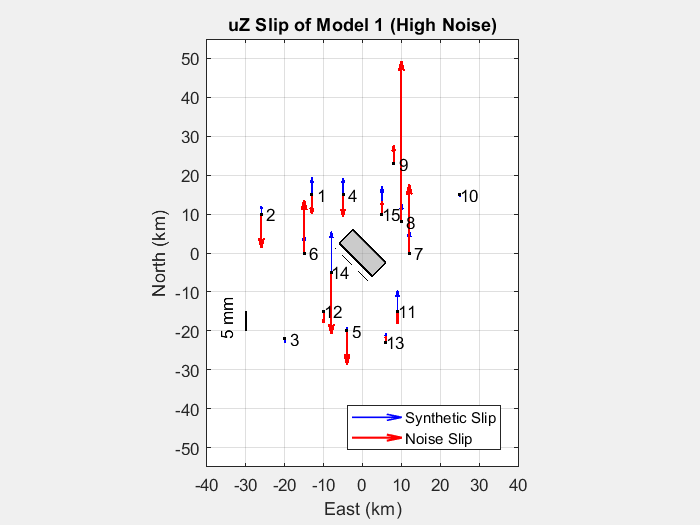

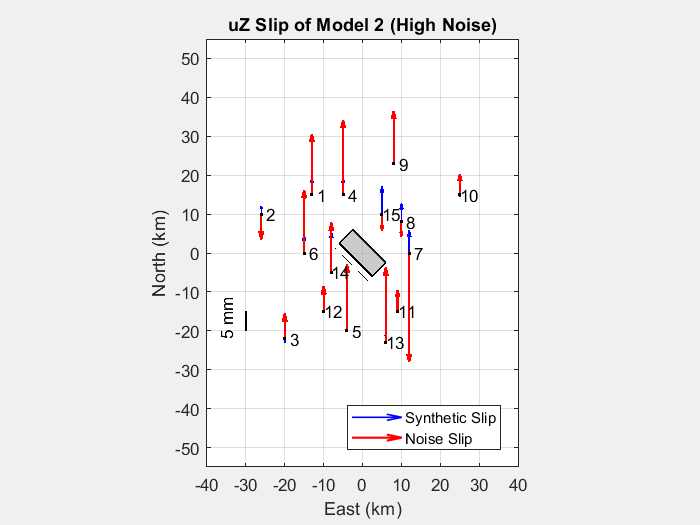

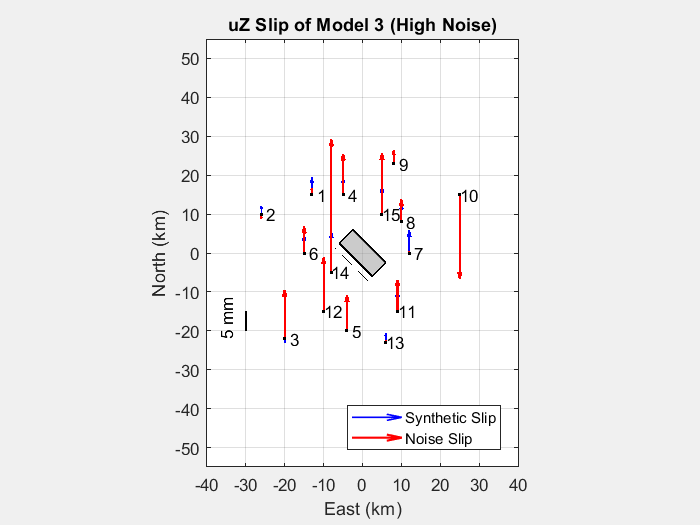

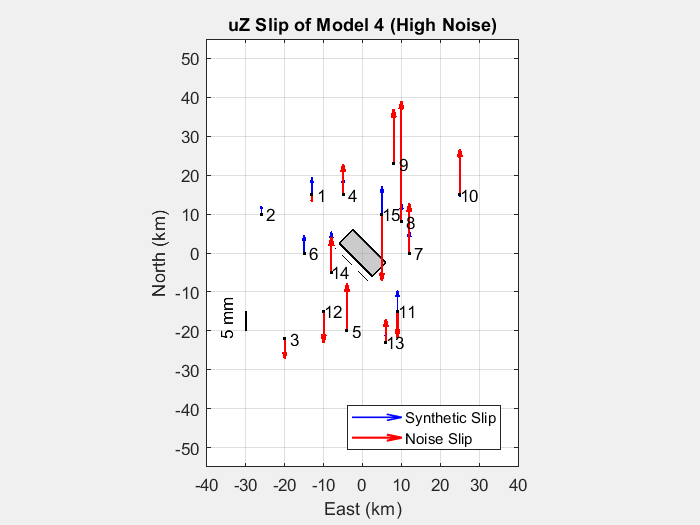

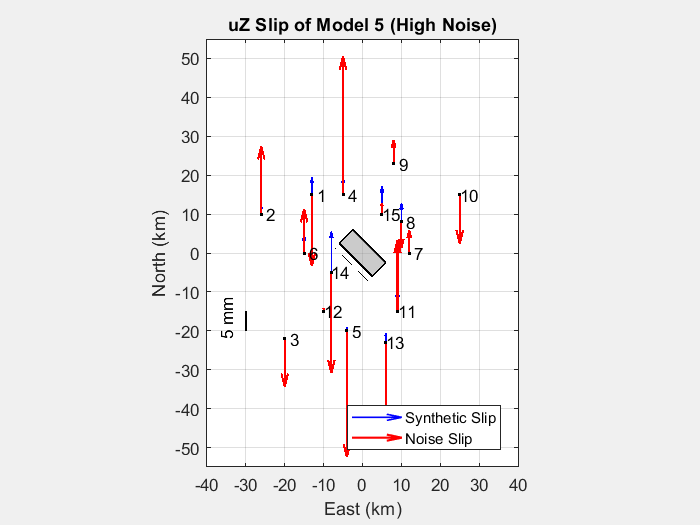

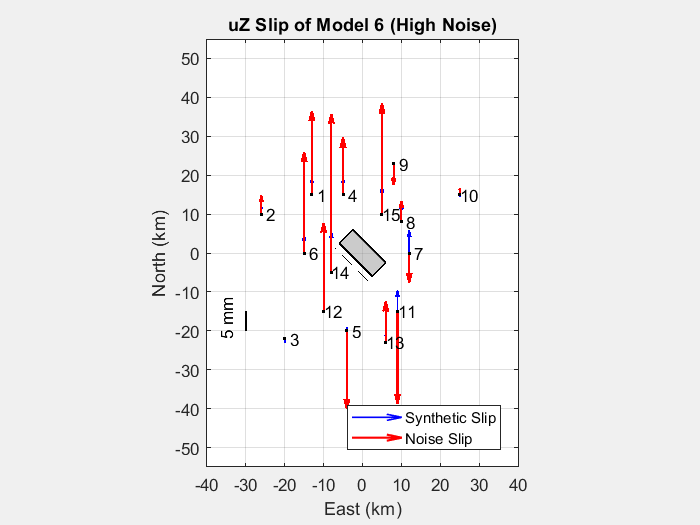

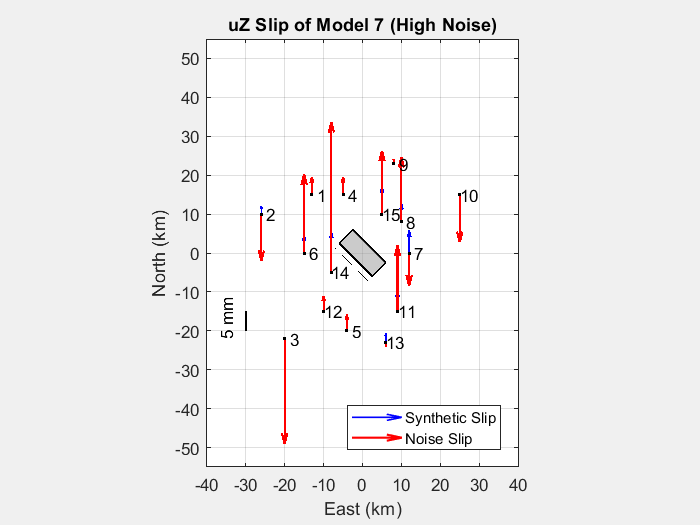

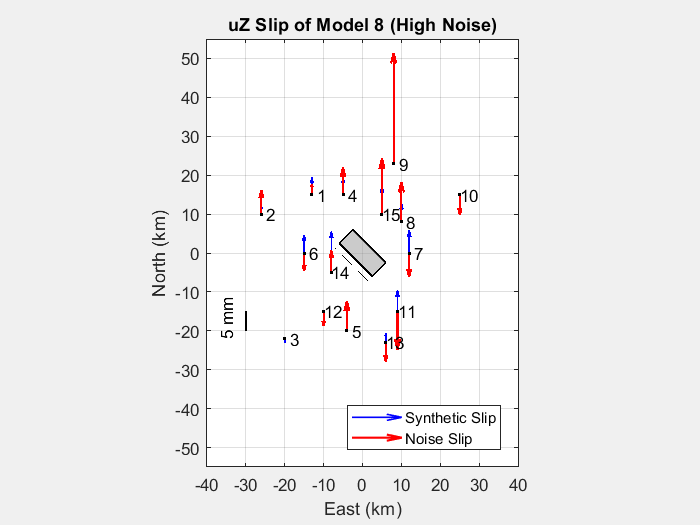

for count = 1:f_models2
    figure()

    % Απεικόνιση ρήγματος
    okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
    hold on

    % Απεικόνιση σημείων - σταθμών
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);

    % Απεικόνιση μετρημένων τιμών ολίσθησης
    p1 = quiver3(E,N,Z,zeros(points,1),uZ*Slip_Scale_z/2,...
        zeros(points,1),'b','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

    % Απεικόνιση τιμών ολίσθησης με θόρυβο
    p2 = quiver3(E,N,Z,zeros(points,1),...
        uZ_New2(:,count)*Slip_Scale_z/2,zeros(points,1),...
        'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);
    
    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'southeast';

    % Σχεδίαση ίχνους
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Ticks αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)
    
    % Κλίμακα για μέγεθος των slips
    obj = scalebar_ed1;
    obj.XLen = 0; obj.YLen = 5;
    obj.YUnit = [num2str(1/(Slip_Scale_z/2)*10^6*obj.YLen) ' mm'];
    obj.hTextY_Pos = [-5,-2];
    obj.Position = [-30,-20];

    % Labels, τίτλος, εύρος αξόνων, γωνία προβολής
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    title(['uZ Slip of Model ' num2str(count) ' (High Noise)'])
    axis([-40 40 -55 55])  % --> Μεταβάλλω ανάλογα
    view([0 90]);            % Για προβολή από πάνω
end

Και σε κατακόρυφη προβολή μαζί με το σφάλμα:

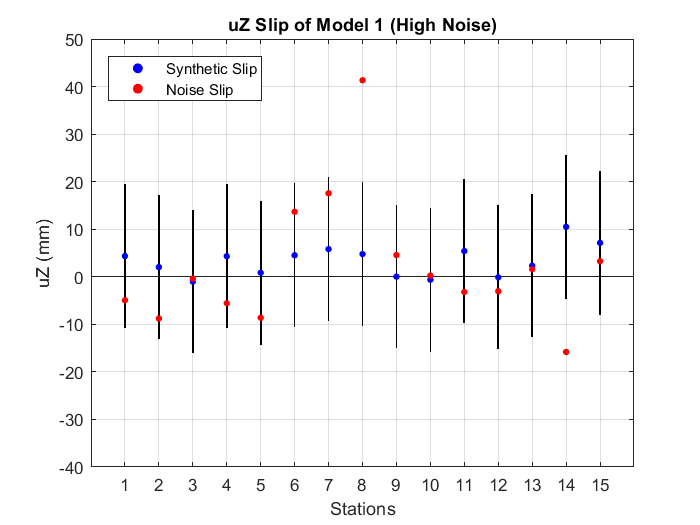

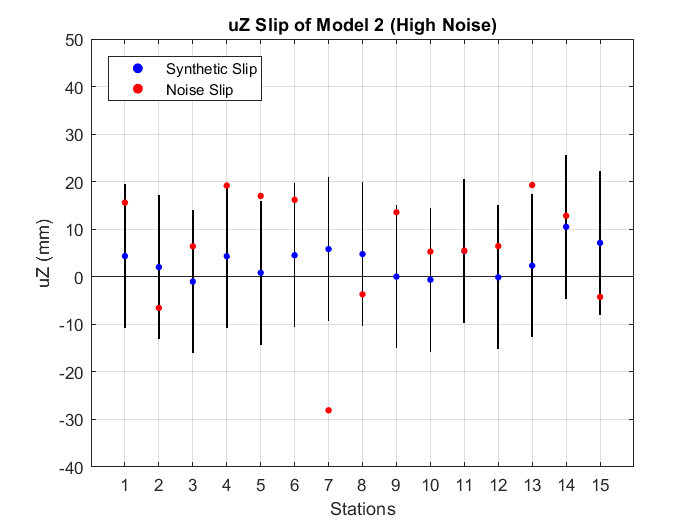

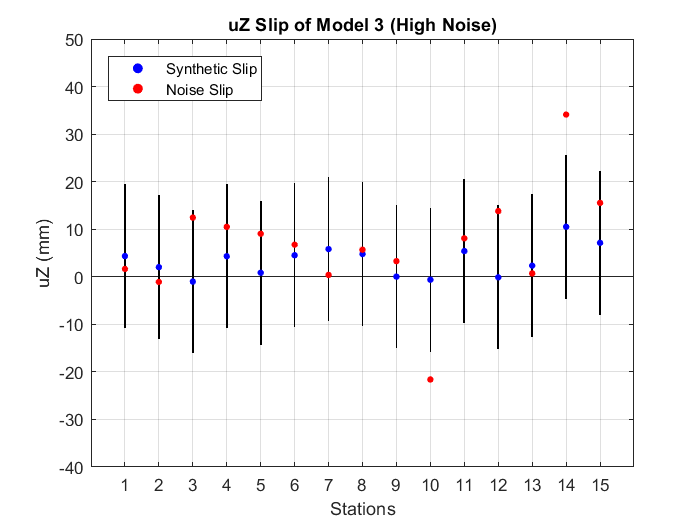

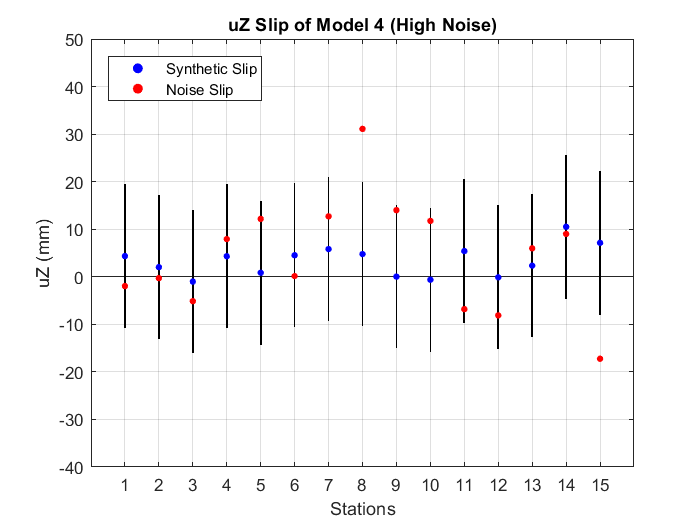

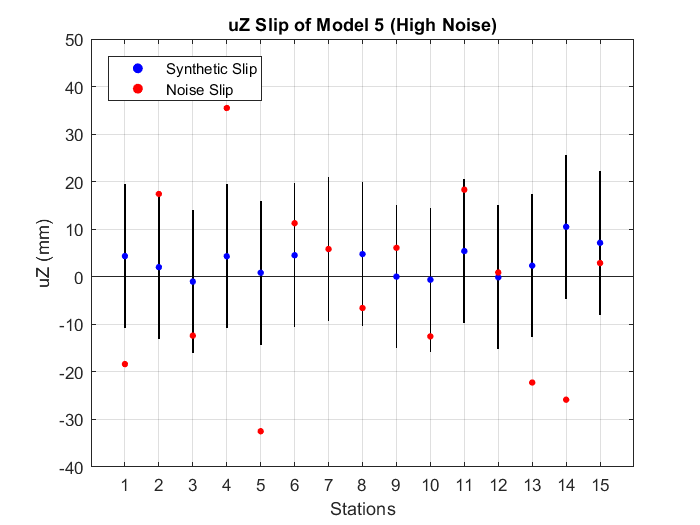

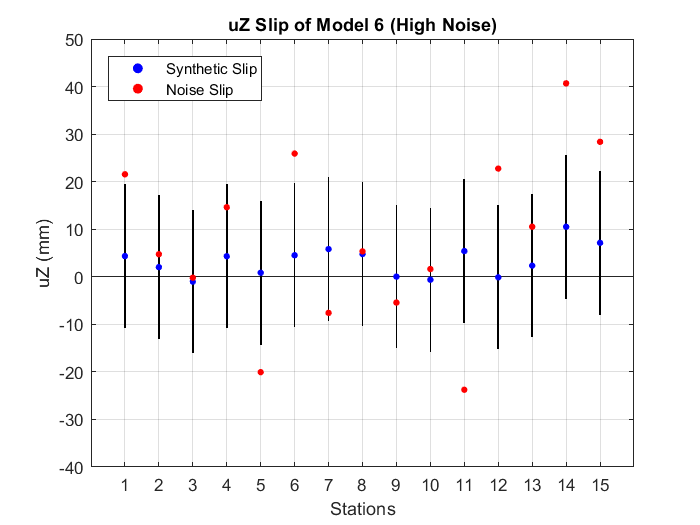

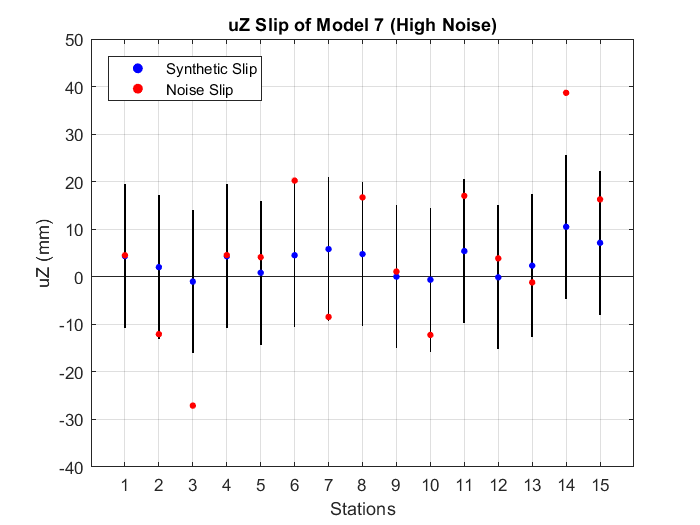

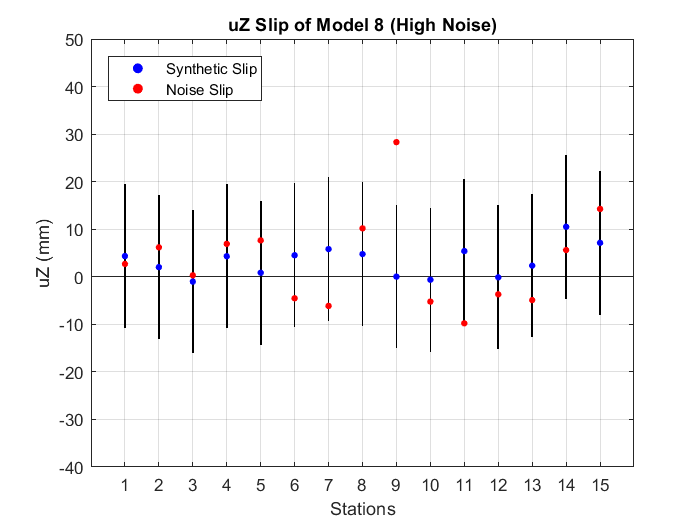

for count = 1:f_models2
    
    figure()
    
    % Η γραμμή σφάλματος, που εκφράζει το εύρος [-σ,σ]
    vert_slip2 = [uZ - sigma_uZ2, repmat(2*sigma_uZ2,points,1)]*10^6;
    h = bar(vert_slip2,0.02,'stacked');
    set(h(1), 'Visible','off')
    hold on
    
    % Μετρήσεις slip
    p1 = scatter(1:points,uZ*10^6,15,'filled','b');
    
    % Τιμές slip με θόρυβο
    p2 = scatter(1:points,uZ_New2(:,count)*10^6,15,'filled','r');
    grid on
    
    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northwest';
    
    % Ticks, Labels και τίτλος
    xticks(1:points);
    yticks(-500:10:500);
    axis([0 points+1 -40 50]) % --> Μεταβάλλω ανάλογα ή αφαιρώ
    xlabel('Stations'); ylabel('uZ (mm)')
    title(['uZ Slip of Model ' num2str(count) ' (High Noise)']);
end

## Θόρυβος στις παραμέτρους του ρήγματος (5%)

Θα δοκιμάσουμε τώρα να δώσουμε τον ίδιο θόρυβο (5% και 20%), αλλά στις αρχικές παραμέτρους του ρήγματος. Ξεκινάμε με μικρό θόρυβο (5%).

**!!! Εάν τρέξουμε το βήμα αυτό δημιουργούνται νέα μοντέλα, καθώς δημιουργείται τυχαίος θόρυβος βάσει του σφάλματος !!!**

n_models3 = 10;   % --> Ο αριθμός των νέων μοντέλων που θα δημιουργηθούν
noise3 = 5;       % --> Ο ποσοστιαίος % θόρυβος

sigma_Depth = repmat(0.01*noise3*Depth,1,n_models3);
sigma_Strike = repmat(0.01*noise3*Strike,1,n_models3);
sigma_Dip1 = repmat(0.01*noise3*Dip,1,n_models3);
sigma_Leng = repmat(0.01*noise3*Leng,1,n_models3);
sigma_Wid1 = repmat(0.01*noise3*Wid,1,n_models3);
sigma_Rake = repmat(0.01*noise3*Rake,1,n_models3);
sigma_Slip = repmat(0.01*noise3*Slip,1,n_models3);

Depth_noise = sigma_Depth .* randn(1,n_models3);
Strike_noise = sigma_Strike .* randn(1,n_models3);
Dip_noise = sigma_Dip1 .* randn(1,n_models3);
Leng_noise = sigma_Leng .* randn(1,n_models3);
Wid_noise = sigma_Wid1 .* randn(1,n_models3);
Rake_noise = sigma_Rake .* randn(1,n_models3);
Slip_noise = sigma_Slip .* randn(1,n_models3);

Depth_New1 = Depth_noise + repmat(Depth,1,n_models3);
Strike_New1 = Strike_noise + repmat(Strike,1,n_models3);
Dip_New1 = Dip_noise + repmat(Dip,1,n_models3);
Leng_New1 = Leng_noise + repmat(Leng,1,n_models3);
Wid_New1 = Wid_noise + repmat(Wid,1,n_models3);
Rake_New1 = Rake_noise + repmat(Rake,1,n_models3);
Slip_New1 = Slip_noise + repmat(Slip,1,n_models3);

Depth_c_New1 = Depth_New1 + sin(Dip_New1*pi/180) .* Wid_New1/2; ...
    % Η okada85 ζητά το Depth του fault centroid

Υπολογίζεται και το ίχνος του ρήγματος (προέκταση του στην επιφάνεια του εδάφους), για τις παραμέτρους με σφάλμα.

trace_A_N_New1 = (sin(Strike_New1*pi/180).*(Wid_New1/2 + Depth_New1./tan...
    (Dip_New1*pi/180)) - cos(Strike_New1*pi/180).*Leng_New1/2)';
trace_B_N_New1 = (sin(Strike_New1*pi/180).*(Wid_New1/2 + Depth_New1./tan...
    (Dip_New1*pi/180)) + cos(Strike_New1*pi/180).*Leng_New1/2)';

trace_A_E_New1 = (-cos(Strike_New1*pi/180).*(Wid_New1/2 + Depth_New1./tan...
    (Dip_New1*pi/180)) - sin(Strike_New1*pi/180).*Leng_New1/2)';
trace_B_E_New1 = (-cos(Strike_New1*pi/180).*(Wid_New1/2 + Depth_New1./tan...
    (Dip_New1*pi/180)) + sin(Strike_New1*pi/180).*Leng_New1/2)';

N_trace_New1 = zeros(n_models3,100);
E_trace_New1 = zeros(n_models3,100);

% Σχετικές συντεταγμένες (East, North) του ίχνους ως προς το fault centroid
for count = 1:n_models3
N_trace_New1(count,:) = linspace(trace_A_N_New1(count),...
    trace_B_N_New1(count),100);
E_trace_New1(count,:) = linspace(trace_A_E_New1(count),...
    trace_B_E_New1(count),100);
end

Και οι συντεταγμένες του ίχνους latitude, longitude:

[lat_A_New1,long_A_New1] = utm2ll((E_c+trace_A_E_New1)*1000,...
    (N_c+trace_A_N_New1)*1000,zone_num);

[lat_B_New1,long_B_New1] = utm2ll((E_c+trace_B_E_New1)*1000,...
    (N_c+trace_B_N_New1)*1000,zone_num);

Υπολογίζονται έτσι νέα uE, uN, uZ με τη διαδικασία του Forward Modeling.

uE_New3 = zeros(points,n_models3);
uN_New3 = zeros(points,n_models3);
uZ_New3 = zeros(points,n_models3);

for count = 1:n_models3
    
    [uE_New3(:,count),uN_New3(:,count),uZ_New3(:,count)] = okada85_ed1...
        (E,N,Depth_c_New1(count),Strike_New1(count),Dip_New1(count),...
        Leng_New1(count),Wid_New1(count),Rake_New1(count),Slip_New1(count),0);
end

% Πίνακες Excel με τα χαρακτηριστικά των νέων ρηγμάτων και τα νέα slips
table_parameters1 = zeros(9,n_models3+1);
table_parameters1(:,1) = [E_c N_c Depth Strike Dip Leng Wid Rake Slip]';

for count = 1:n_models3
    
     start = (count-1)*3 + 1;
     start1 = (count-1)*2 + 1;
    
     table_slips_New3(:,start:start+2) = [uE_New3(:,count) ...
     uN_New3(:,count) uZ_New3(:,count)]*10^5;
    
    
     table_parameters1(:,count+1) = [E_c N_c Depth_New1(count)...
        Strike_New1(count) Dip_New1(count) Leng_New1(count)...
        Wid_New1(count) Rake_New1(count) Slip_New1(count)*10^5]';
    
     table_AB_par1(start1:start1+1,:) = [trace_A_E_New1(count)...
         trace_A_N_New1(count) trace_A_E_New1(count)+E_c...
         trace_A_N_New1(count)+N_c long_A_New1(count)...
         lat_A_New1(count); ...
         trace_B_E_New1(count) trace_B_N_New1(count)...
         trace_B_E_New1(count)+E_c trace_B_N_New1(count)+N_c...
         long_B_New1(count) lat_B_New1(count)];
        
end

Επιλέγουμε πόσα θέλουμε να απεικονιστούν για σύγκριση με το αρχικό μοντέλο. Αρχικά στο επίπεδο East, North.

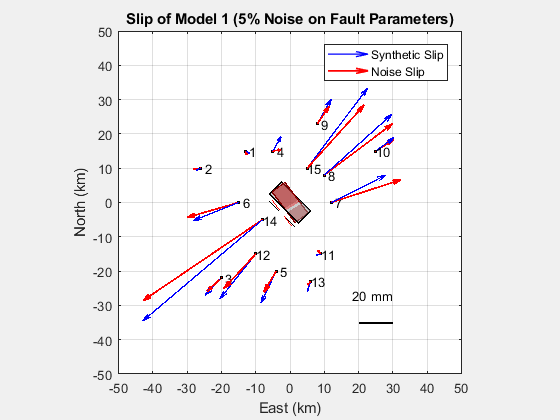

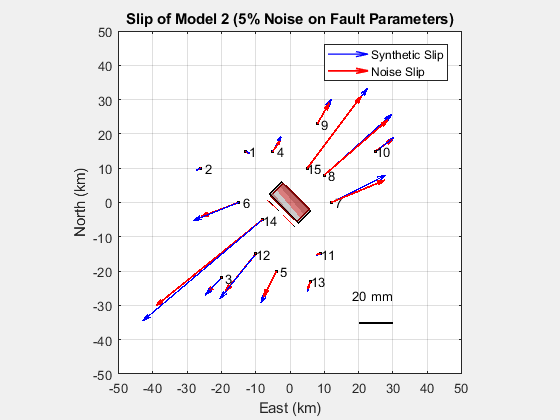

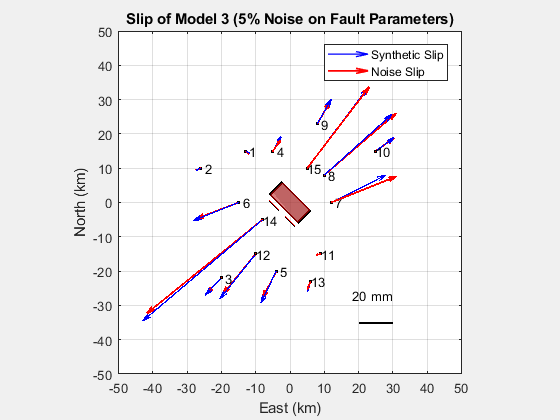

f_models3 = 3;   % --> Δώσε πόσα μοντέλα θέλεις να απεικονιστούν

for count = 1:f_models3

    figure()

    % Απεικόνιση αρχικού ρήγματος
    [uE,uN,uZ] = okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,...
        Rake,Slip,0,'plot');
    hold on

    % Απεικόνιση σημείων
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);

    % Απεικόνιση συνθετικών δεδομένων slip
    p1 = quiver3(E,N,Z,uE*Slip_Scale,uN*Slip_Scale,uZ*...
        Slip_Scale,'b','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

    % Σχεδίαση ίχνους αρχνικού ρήγματος
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Απεικόνιση του νέου ρήγματος
    okada85_ed2(E,N,Depth_c_New1(count),Strike_New1(count),...
        Dip_New1(count),Leng_New1(count),Wid_New1(count),...
        Rake_New1(count),Slip_New1(count),0);

    % Απεικόνιση νέων τιμών slip
    p2 = quiver3(E,N,Z,uE_New3(:,count)*Slip_Scale,uN_New3(:,count)...
        *Slip_Scale,uZ_New3(:,count)*Slip_Scale,'r','AutoScale',...
        'off','MaxHeadSize',0.1,'LineWidth',1.3);

    % Σχεδίαση ίχνους του νέου ρήγματος
    plot3(E_trace_New1(count,:),N_trace_New1(count,:),Z_trace,'r--')

    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    % Ticks αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)

    % Κλίμακα μεγέθους slips
    obj = scalebar_ed1;
    obj.XLen = 10; obj.YLen = 0;
    obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
    obj.hTextX_Pos = [-2,8];
    obj.Position = [20,-35];

    % Labels, εύρος αξόνων, γωνία θέασης και τίτλος
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    axis([-50 50 -50 50])  % Μεταβάλλω ανάλογα
    view([0 90]);          % Για προβολή από πάνω
    title(['Slip of Model ' num2str(count) ' (5% Noise on Fault Parameters)'])
end

Για τις κατακόρυφες ολισθήσεις:

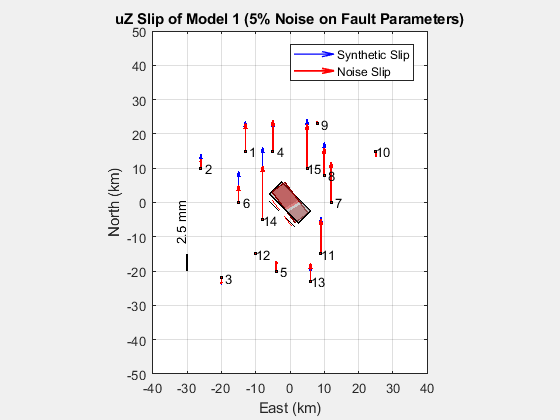

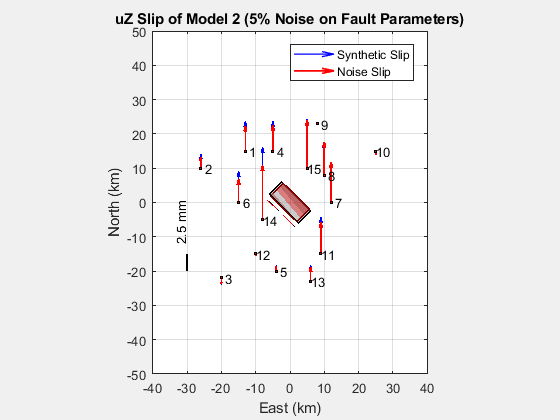

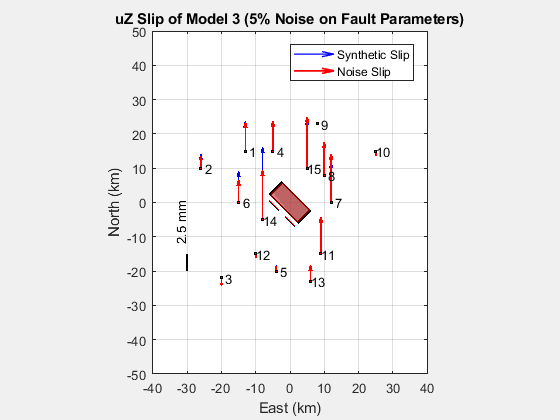

for count = 1:f_models3

    figure()

    % Απεικόνιση αρχικού ρήγματος
    [uE,uN,uZ] = okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,...
        Rake,Slip,0,'plot');
    hold on

    % Απεικόνιση σημείων
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);

    % Απεικόνιση συνθετικών δεδομένων slip
    p1 = quiver3(E,N,Z,zeros(points,1),uZ*Slip_Scale_z,zeros(points,1),...
        'b','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1);

    % Σχεδίαση ίχνους αρχνικού ρήγματος
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Απεικόνιση του νέου ρήγματος
    okada85_ed2(E,N,Depth_c_New1(count),Strike_New1(count),...
        Dip_New1(count),Leng_New1(count),Wid_New1(count),...
        Rake_New1(count),Slip_New1(count),0);

    % Απεικόνιση νέων τιμών slip
    p2 = quiver3(E,N,Z,zeros(points,1),uZ_New3(:,count)...
        *Slip_Scale_z,zeros(points,1),'r','AutoScale',...
        'off','MaxHeadSize',0.1,'LineWidth',1.3);

    % Σχεδίαση ίχνους του νέου ρήγματος
    plot3(E_trace_New1(count,:),N_trace_New1(count,:),Z_trace,'r--')

    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    % Ticks αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)

    % Κλίμακα μεγέθους slips
    obj = scalebar_ed1;
    obj.XLen = 0; obj.YLen = 5;
    obj.YUnit = [num2str(1/Slip_Scale_z*10^6*obj.YLen) ' mm'];
    obj.hTextY_Pos = [-2,8];
    obj.Position = [-30,-20];

    % Labels, εύρος αξόνων, γωνία θέασης και τίτλος
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    axis([-40 40 -50 50])  % Μεταβάλλω ανάλογα
    view([0 90]);          % Για προβολή από πάνω
    title(['uZ Slip of Model ' num2str(count) ' (5% Noise on Fault Parameters)'])
end

Και σε κατακόρυφη προβολή σε διάγραμμα stems:

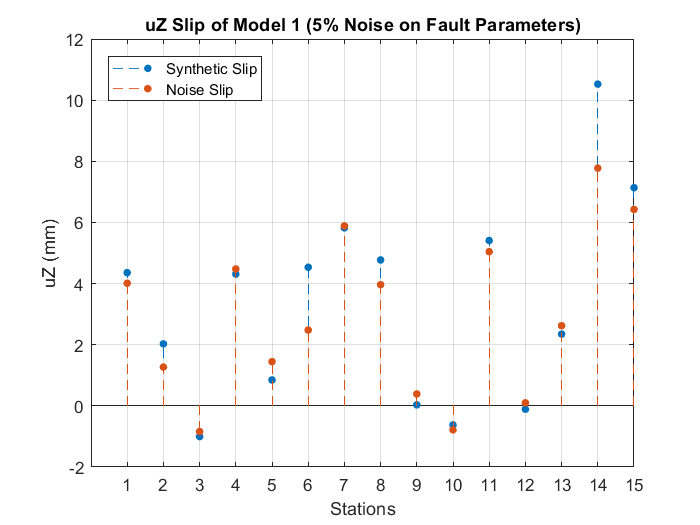

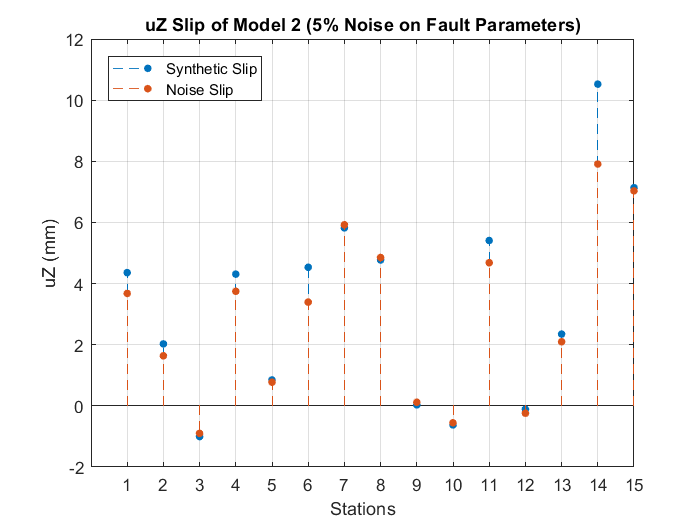

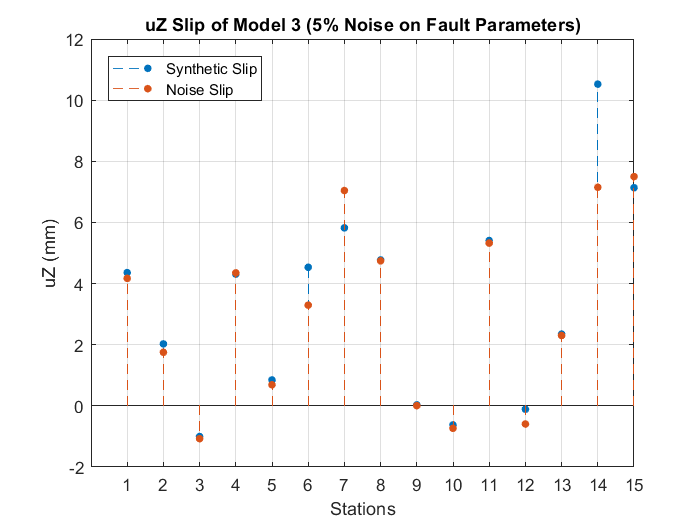

for count = 1:f_models3
    
    figure()
    
    % Απεικόνιση μετρήσεων και νέων τιμών slips σε διάγραμμα stems
    p1 = stem(1:points,[uZ uZ_New3(:,count)]*10^6,'filled',...
        'MarkerSize',4,'LineStyle','--');
    
    % Υπόμνημα
    leg = legend(p1,{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northwest';
    
    % Ticks, εύρος αξόνων, Labels και τίτλος
    grid on
    xticks(1:points);
    xlabel('Stations'); ylabel('uZ (mm)')
    title(['uZ Slip of Model ' num2str(count) ' (5% Noise on Fault' ...
        ' Parameters)']);

end

## Θόρυβος στις παραμέτρους του ρήγματος (20%)

Θα δώσουμε τώρα μεγάλο θόρυβο (20%) στις αρχικές παραμέτρους του ρήγματος.

**!!! Εάν τρέξουμε το βήμα αυτό δημιουργούνται νέα μοντέλα, καθώς δημιουργείται τυχαίος θόρυβος βάσει του σφάλματος !!!**

n_models4 = 10;   % --> Ο αριθμός των νέων μοντέλων που θα δημιουργηθούν
noise4 = 20;      % --> Ο ποσοστιαίος % θόρυβος

sigma_Depth = repmat(0.01*noise4*Depth,1,n_models3);
sigma_Strike = repmat(0.01*noise4*Strike,1,n_models3);
sigma_Dip1 = repmat(0.01*noise4*Dip,1,n_models3);
sigma_Leng = repmat(0.01*noise4*Leng,1,n_models3);
sigma_Wid1 = repmat(0.01*noise4*Wid,1,n_models3);
sigma_Rake = repmat(0.01*noise4*Rake,1,n_models3);
sigma_Slip = repmat(0.01*noise4*Slip,1,n_models3);

Depth_noise = sigma_Depth .* randn(1,n_models4);
Strike_noise = sigma_Strike .* randn(1,n_models4);
Dip_noise = sigma_Dip1 .* randn(1,n_models4);
Leng_noise = sigma_Leng .* randn(1,n_models4);
Wid_noise = sigma_Wid1 .* randn(1,n_models4);
Rake_noise = sigma_Rake .* randn(1,n_models4);
Slip_noise = sigma_Slip .* randn(1,n_models4);

Depth_New2 = Depth_noise + repmat(Depth,1,n_models4);
Strike_New2 = Strike_noise + repmat(Strike,1,n_models4);
Dip_New2 = Dip_noise + repmat(Dip,1,n_models4);
Leng_New2 = Leng_noise + repmat(Leng,1,n_models4);
Wid_New2 = Wid_noise + repmat(Wid,1,n_models4);
Rake_New2 = Rake_noise + repmat(Rake,1,n_models4);
Slip_New2 = Slip_noise + repmat(Slip,1,n_models4);

Depth_c_New2 = Depth_New2 + sin(Dip_New2*pi/180) .* Wid_New2/2; ...
    % Η okada85 ζητά το Depth του fault centroid

Υπολογίζεται και το ίχνος του ρήγματος (προέκταση του στην επιφάνεια του εδάφους), για τις παραμέτρους με σφάλμα (συντεταγμένες [East,North] σε σχέση με το fault centroid.

trace_A_N_New2 = (sin(Strike_New2*pi/180).*(Wid_New2/2 + Depth_New2./tan...
    (Dip_New2*pi/180)) - cos(Strike_New2*pi/180).*Leng_New2/2)';
trace_B_N_New2 = (sin(Strike_New2*pi/180).*(Wid_New2/2 + Depth_New2./tan...
    (Dip_New2*pi/180)) + cos(Strike_New2*pi/180).*Leng_New2/2)';

trace_A_E_New2 = (-cos(Strike_New2*pi/180).*(Wid_New2/2 + Depth_New2./tan...
    (Dip_New2*pi/180)) - sin(Strike_New2*pi/180).*Leng_New2/2)';
trace_B_E_New2 = (-cos(Strike_New2*pi/180).*(Wid_New2/2 + Depth_New2./tan...
    (Dip_New2*pi/180)) + sin(Strike_New2*pi/180).*Leng_New2/2)';

N_trace_New2 = zeros(n_models4,100);
E_trace_New2 = zeros(n_models4,100);

for count = 1:n_models4
N_trace_New2(count,:) = linspace(trace_A_N_New2(count),...
    trace_B_N_New2(count),100);
E_trace_New2(count,:) = linspace(trace_A_E_New2(count),...
    trace_B_E_New2(count),100);
end

Και οι συντεταγμένες του ίχνους σε latitude, longitude.

[lat_A_New2,long_A_New2] = utm2ll((E_c+trace_A_E_New2)*1000,...
    (N_c+trace_A_N_New2)*1000,zone_num);

[lat_B_New2,long_B_New2] = utm2ll((N_c+trace_B_N_New2)*1000,...
    (E_c+trace_B_E_New2)*1000,zone_num);

Υπολογίζονται έτσι νέα uE, uN, uZ, με τη διαδικασία του Forward Modeling.

uE_New4 = zeros(points,n_models4);
uN_New4 = zeros(points,n_models4);
uZ_New4 = zeros(points,n_models4);

for count = 1:n_models4
    
    [uE_New4(:,count),uN_New4(:,count),uZ_New4(:,count)] = okada85_ed1...
        (E,N,Depth_c_New2(count),Strike_New2(count),Dip_New2(count),...
        Leng_New2(count),Wid_New2(count),Rake_New2(count),Slip_New2(count),0);
end

% Πίνακες Excel με τα slips και τα χαρακτηριστικά των νέων ρηγμάτων
table_parameters2 = zeros(9,n_models4+1);
table_parameters2(:,1) = [E_c N_c Depth Strike Dip Leng Wid Rake Slip]';

for count = 1:n_models4
    
     start = (count-1)*3 + 1;
     start1 = (count-1)*2 + 1;
    
     table_slips_New4(:,start:start+2) = [uE_New4(:,count) ...
     uN_New4(:,count) uZ_New4(:,count)]*10^5;
    
    
     table_parameters2(:,count+1) = [E_c N_c Depth_New2(count)...
        Strike_New2(count) Dip_New2(count) Leng_New2(count)...
        Wid_New2(count) Rake_New2(count) Slip_New2(count)*10^5]';
    
     table_AB_par2(start1:start1+1,:) = [trace_A_E_New2(count)...
         trace_A_N_New2(count) trace_A_E_New2(count)+E_c...
         trace_A_N_New2(count)+N_c long_A_New2(count)...
         lat_A_New2(count); ...
         trace_B_E_New2(count) trace_B_N_New2(count)...
         trace_B_E_New2(count)+E_c trace_B_N_New2(count)+N_c...
         long_B_New2(count) lat_B_New2(count)];
      
end

Επιλέγουμε πόσα θέλουμε να απεικονιστούν για σύγκριση με το αρχικό μοντέλο.

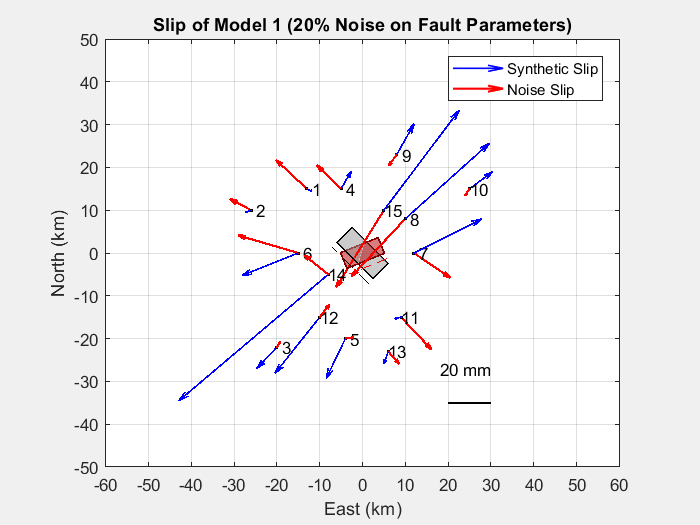

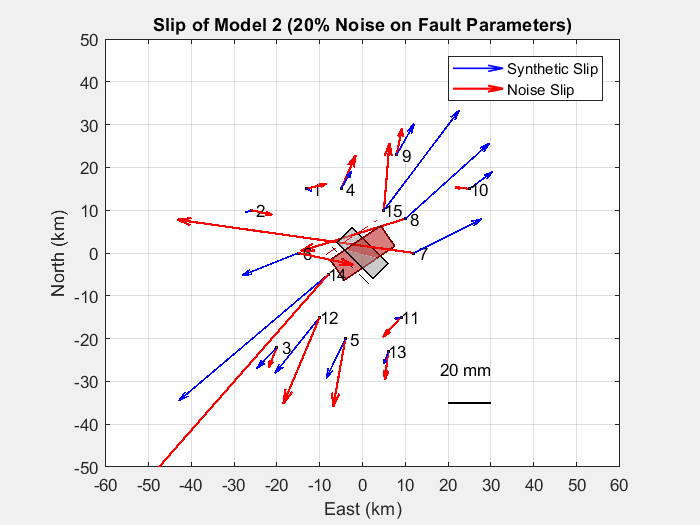

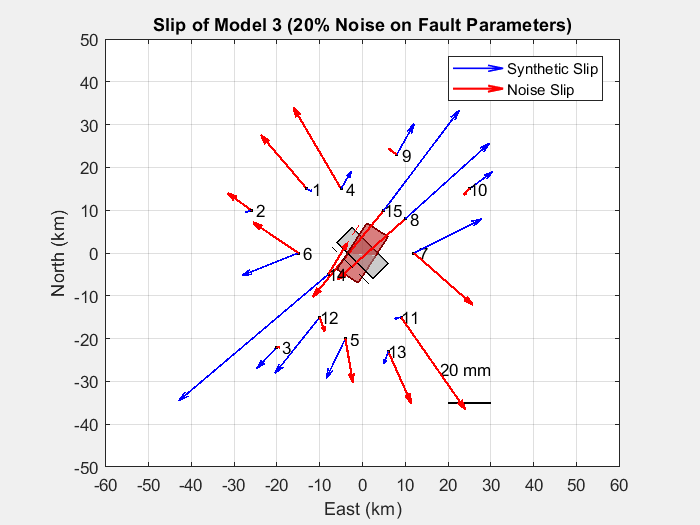

f_models4 = 3;   % --> Δώσε πόσα μοντέλα θέλεις να απεικονιστούν

for count = 1:f_models4

figure()
    
    % Απεικόνιση του αρχικού ρήγματος
    okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
    hold on

    % Απεικόνιση των σημείων - σταθμών
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);  
    
    % Απεικόνιση των συνθετικών μετρήσεων
    p1 = quiver3(E,N,Z,uE*Slip_Scale,uN*Slip_Scale,...
        uZ*Slip_Scale,'b','AutoScale','off','MaxHeadSize',0.1, 'LineWidth',1);

    % Σχεδίαση του ίχνους του αρχικού ρήγματος
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Απεικόνιση του νέου ρήγματος
    okada85_ed2(E,N,Depth_c_New2(count),Strike_New2(count),...
        Dip_New2(count),Leng_New2(count),Wid_New2(count),...
        Rake_New2(count),Slip_New2(count),0);

    % Απεικόνιση των νέων τιμών slip
    p2 = quiver3(E,N,Z,uE_New4(:,count)*Slip_Scale,...
        uN_New4(:,count)*Slip_Scale,uZ_New4(:,count)*...
        Slip_Scale,'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);    

    % Σχεδίαση του ίχνους του νέου ρήγματος
    plot3(E_trace_New2(count,:),N_trace_New2(count,:),Z_trace,'r--')

    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northeast';

    % Ticks των αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)
    
    % Κλίμακα μεγέθους των slip
    obj = scalebar_ed1;
    obj.XLen = 10; obj.YLen = 0;
    obj.XUnit = [num2str(1/Slip_Scale*10^6*obj.XLen) ' mm'];
    obj.hTextX_Pos = [-2,8];
    obj.Position = [20,-35];

    % Labels, εύρος αξόνων, γωνία θέασης και τίτλος
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    axis([-30 30 -30 30])  % Μεταβάλλω ανάλογα
    view([0 90]);          % Για προβολή από πάνω
    title(['Slip of Model ' num2str(count) ' (20% Noise on Fault Parameters)'])
end

Για τις κατακόρυφες ολισθήσεις:

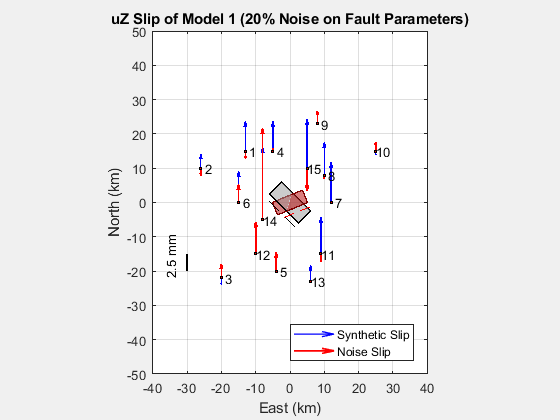

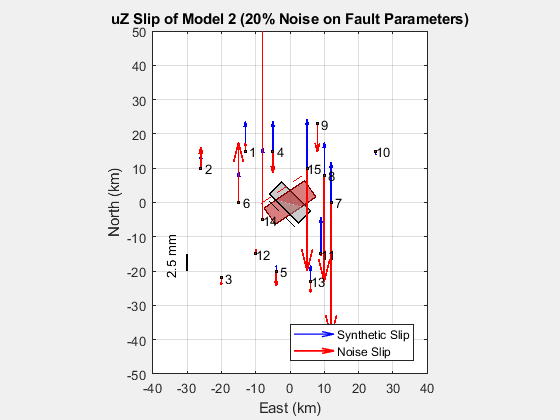

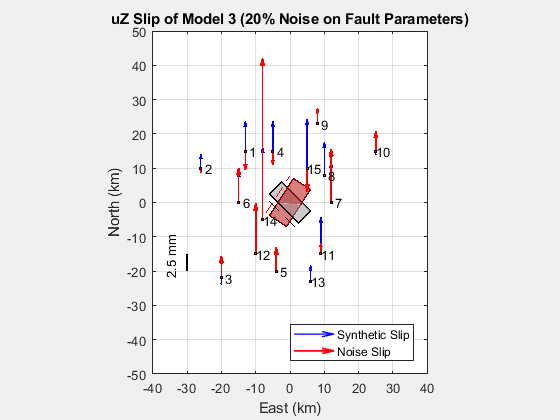

for count = 1:f_models4

figure()
    
    % Απεικόνιση του αρχικού ρήγματος
    okada85_ed1(E,N,Depth_c,Strike,Dip,Leng,Wid,Rake,Slip,0);
    hold on

    % Απεικόνιση των σημείων - σταθμών
    plot3(E,N,Z,'.k')
    text(E,N,Z,points_names);  
    
    % Απεικόνιση των συνθετικών μετρήσεων
    p1 = quiver3(E,N,Z,zeros(points,1),uZ*Slip_Scale_z,...
        zeros(points,1),'b','AutoScale','off','MaxHeadSize',0.1, 'LineWidth',1);

    % Σχεδίαση του ίχνους του αρχικού ρήγματος
    plot3(E_trace,N_trace,Z_trace,'k--')

    % Απεικόνιση του νέου ρήγματος
    okada85_ed2(E,N,Depth_c_New2(count),Strike_New2(count),...
        Dip_New2(count),Leng_New2(count),Wid_New2(count),...
        Rake_New2(count),Slip_New2(count),0);

    % Απεικόνιση των νέων τιμών slip
    p2 = quiver3(E,N,Z,zeros(points,1),...
        uZ_New4(:,count)*Slip_Scale_z,zeros(points,1),...
        'r','AutoScale','off','MaxHeadSize',0.1,'LineWidth',1.3);    

    % Σχεδίαση του ίχνους του νέου ρήγματος
    plot3(E_trace_New2(count,:),N_trace_New2(count,:),Z_trace,'r--')

    % Υπόμνημα
    leg = legend([p1 p2],{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'southeast';

    % Ticks των αξόνων
    xticks(-500:10:500)
    yticks(-500:10:500)
    zticks(-500:10:500)
    
    % Κλίμακα μεγέθους των slip
    obj = scalebar_ed1;
    obj.XLen = 0; obj.YLen = 5;
    obj.YUnit = [num2str(1/Slip_Scale_z*10^6*obj.YLen) ' mm'];
    obj.hTextY_Pos = [-5,-2];
    obj.Position = [-30,-20];

    % Labels, εύρος αξόνων, γωνία θέασης και τίτλος
    xlabel('East (km)'); ylabel('North (km)'); zlabel('Vertical (km)')
    axis([-40 40 -50 50])  % Μεταβάλλω ανάλογα
    view([0 90]);          % Για προβολή από πάνω
    title(['uZ Slip of Model ' num2str(count) ' (20% Noise on Fault Parameters)'])
end

Και σε κατακόρυφη προβολή σε διάγραμμα stems:

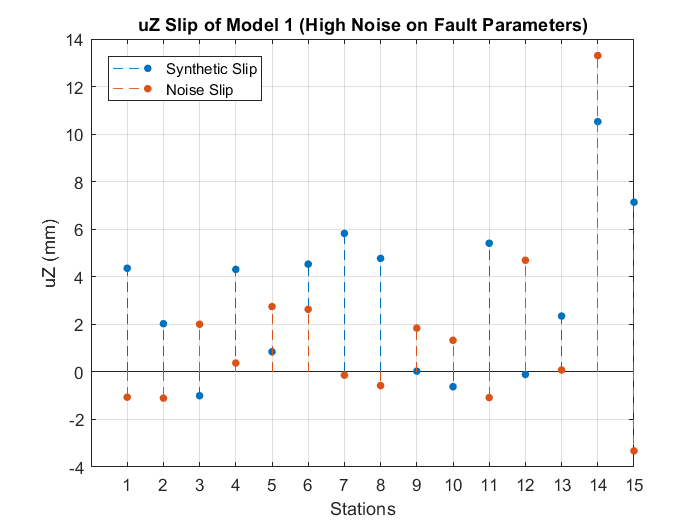

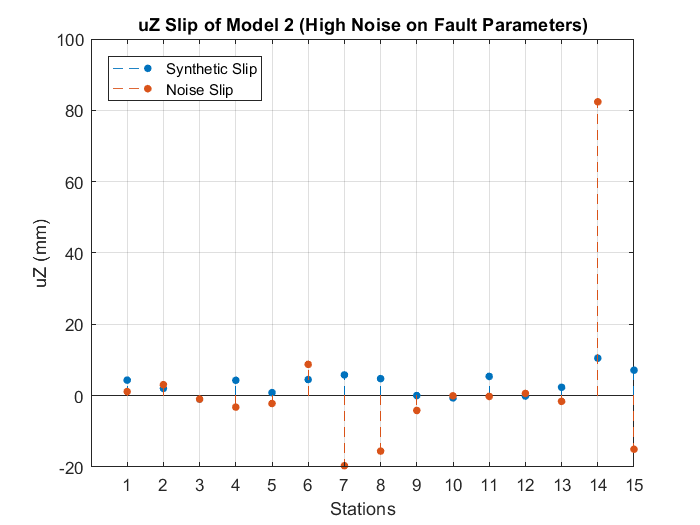

for count = 1:f_models4
    
    figure()
    
    % Απεικόνιση μετρήσεων και νέων τιμών slips σε διάγραμμα stems
    p1 = stem(1:points,[uZ uZ_New4(:,count)]*10^6,'filled',...
        'MarkerSize',4,'LineStyle','--');

    % Υπόμνημα
    leg = legend(p1,{'Synthetic Slip','Noise Slip'});
    leg.AutoUpdate = 'off';
    leg.Location = 'northwest';
    
    % Ticks, Labels και τίτλος
    grid on
    xticks(1:points);
    xlabel('Stations'); ylabel('uZ (mm)')
    title(['uZ Slip of Model ' num2str(count) ' (High Noise on Fault' ...
        ' Parameters)']);

end

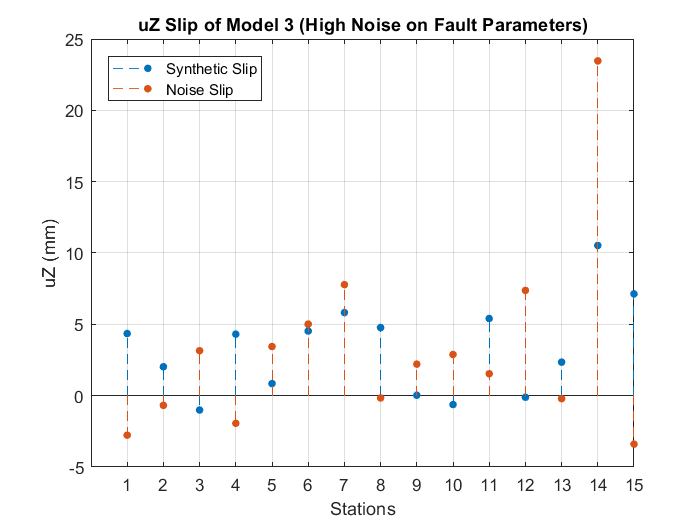


% Αποθήκευση του Workspace 
save Workspace_ForwardModeling.mat